# Glenoid Processing Tests using GIBBON

## Starting Notes

This code uses the right scapula and humerus extracted from the Visible Human CT dataset to trial processing steps for FE analysis with a focus on using the GIBBON toolbox. The scapula and humerus meshes were exported from the Materialise suite of software as ASCII STL's in their original coordinate system (scapula.stl and humerus.stl). The only processing performed on these meshes was to uniformly mesh them to have a target triangle edge length of 1mm. This means they still aren't necessraily too smooth and could do with some extra processing or better masking.

There are also a number of additional objects exported that fit these meshes:

- **deepGlenoidCentre.txt:** includes the 3D coordinate of the estimated deepest point at the centre of the glenoid. This should serve as the origin for the scapula coordinate system.

- **glenoidPlanes.xml:** contains the planes fitted around the glenoid surface and glenoid axes. These planes represent the XY, XZ and YZ planes of the glenoid surface, with: (i) the Z axes being the normal away from a plane fitted to the glenoid surface; (ii) the Y axes being parralel to a line made by the supraglenoid and infraglenoid tubercle; and (iii) the X axes being the cross product of these remaining axes, respresenting the anterior-posterio aspect of the glenoid.

- **glenoidRimPoints.txt:** includes the 3D coordinates of a number of points estimated to fall on the glenoid rim. These are mainly estimated from the coronal plane slices of the CT, whereby the closest points/edges to the humerus are selected. They may not fit exactly on the glenoid mesh due to the potential small amount of smoothing done in uniformly remeshing.

- **humeralHeadSphere.txt:** includes the 3D coordinates of the centre and the radius measurement of a sphere fitted to the humeral head mesh.

This code includes a focus on generating cartilage on the surfaces of these structures, using slicing and extending features recently added to GIBBON toolbox, as per the Github issues #62 ([https://github.com/gibbonCode/GIBBON/issues/62](https://github.com/gibbonCode/GIBBON/issues/62)) and #63 ([https://github.com/gibbonCode/GIBBON/issues/63](https://github.com/gibbonCode/GIBBON/issues/63)).

Settings for script

warning off
fontSize = 25;

## Import STL's

Load and visualise STL files

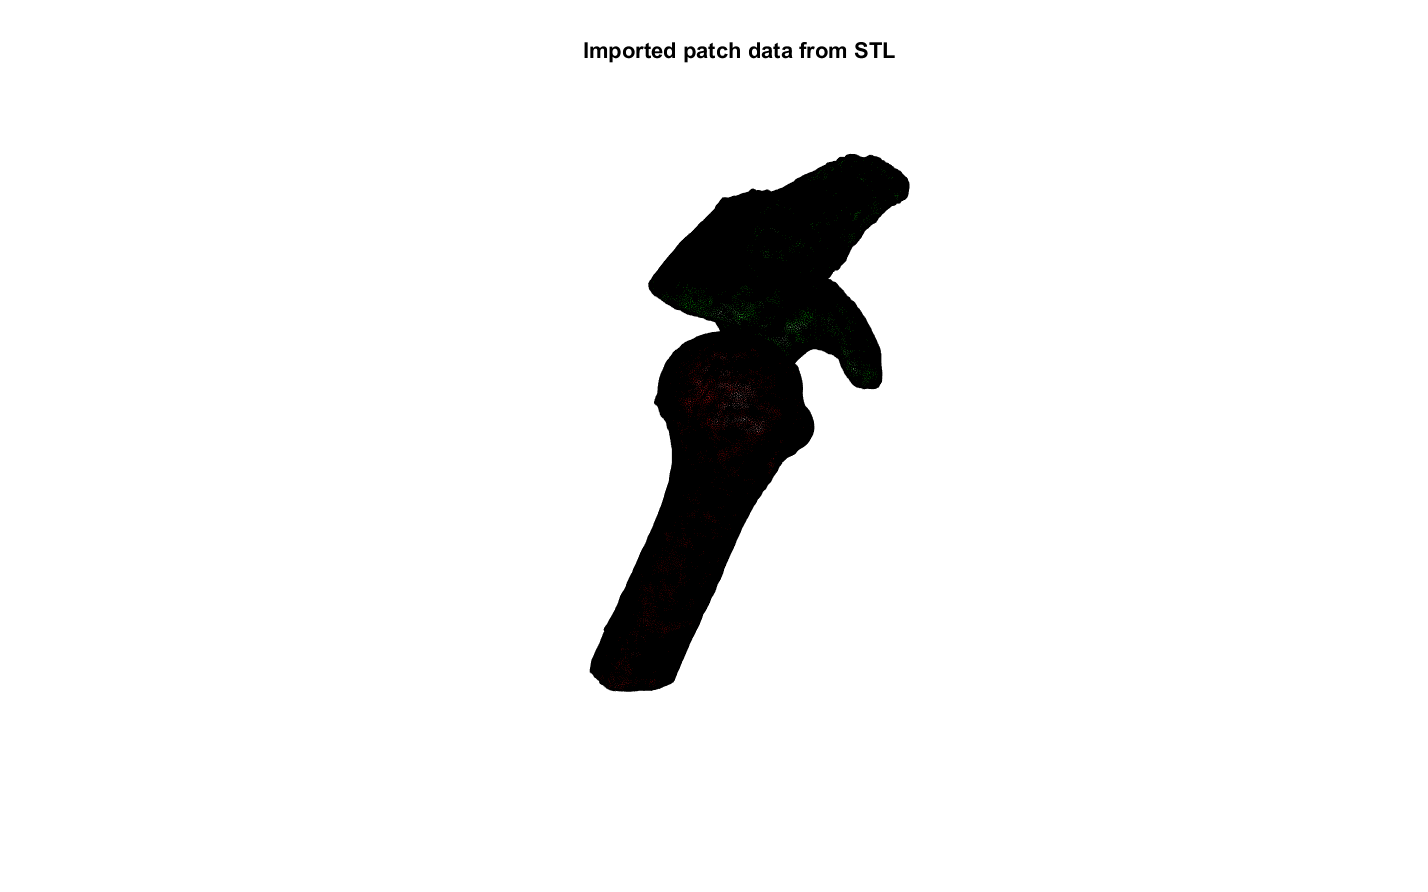

%Load STLs
scapulaSTL = import_STL('scapula.stl');
humerusSTL = import_STL('humerus.stl');
surfaceSTL = import_STL('glenoidSurface.stl');

%Extract the faces and vertices
scapulaF = scapulaSTL.solidFaces{1};
scapulaV = scapulaSTL.solidVertices{1};
humerusF = humerusSTL.solidFaces{1};
humerusV = humerusSTL.solidVertices{1};
surfaceF = surfaceSTL.solidFaces{1};
surfaceV = surfaceSTL.solidVertices{1};

%Merge vertices
[scapulaF,scapulaV] = mergeVertices(scapulaF,scapulaV);
[humerusF,humerusV] = mergeVertices(humerusF,humerusV);
[surfaceF,surfaceV] = mergeVertices(surfaceF,surfaceV);

%Plot the models
cFigure;
title('Imported patch data from STL','fontSize',25);
gpatch(scapulaF,scapulaV,'g','k',1,1e-5);
hold on
gpatch(humerusF,humerusV,'r','k',1,1e-5);
axisGeom;
camlight('headlight');
lighting phong; axis off;

## Import Measurements Data

Import the associated measurements for the scapula and humerus meshes.

%Load the deep glenoid point text
%Read in with line delimiter
C = importdata('deepGlenoidCentre.txt','\n');
%Identify the row with the point label
for rr = 1:length(C)
    rowInd(rr) = contains(C{rr,1},'deepGlenoid');
end
clear rr
%Extract the relevant row
rowTxt = C{rowInd,1};
%Split the string by spaces
rowSplit = strsplit(rowTxt,' ');
%The X,Y,Z coordinates are now in the 2nd, 3rd and 4th cells
landmarks.deepGlenoid(1) = str2double(rowSplit(2));
landmarks.deepGlenoid(2) = str2double(rowSplit(3));
landmarks.deepGlenoid(3) = str2double(rowSplit(4));
%Cleanup
clear C rowInd rowTxt rowSplit

%Load the glenoid rim points
%Read in with line delimiter
C = importdata('glenoidRimPoints.txt','\n');
%Identify the row with the point label
for rr = 1:length(C)
    rowInd(rr) = contains(C{rr,1},'glenoidRim');
end
clear rr
%Extract the relevant row
rowTxt = C(rowInd,1);
%Loop through the number of points
for pp = 1:length(rowTxt)
    %Split the string by spaces
    rowSplit = strsplit(rowTxt{pp},' ');
    %The name is now in the first cell
    %The X,Y,Z coordinates are now in the 2nd, 3rd and 4th cells
    landmarks.(char(rowSplit(1)))(1) = str2double(rowSplit(2));
    landmarks.(char(rowSplit(1)))(2) = str2double(rowSplit(3));
    landmarks.(char(rowSplit(1)))(3) = str2double(rowSplit(4));
    %Create a variable for the glenoid rim names
    glenoidRimLabels{pp} = (char(rowSplit(1)));
end
clear pp
%Cleanup
clear C rowInd rowTxt rowSplit

%Load the humeral head sphere text
%Read in with line delimiter
C = importdata('humeralHeadSphere.txt','\n');
%Identify the row with the point label
for rr = 1:length(C)
    rowInd(rr) = contains(C{rr,1},'humeralHead');
end
clear rr
%Extract the relevant row
rowTxt = C{rowInd,1};
%Split the string by spaces
rowSplit = strsplit(rowTxt,' ');
%The X,Y,Z coordinates are now in the 2nd, 3rd and 4th cells
%The radius size is now in the 5th cell
landmarks.humeralHeadCentre(1) = str2double(rowSplit(2));
landmarks.humeralHeadCentre(2) = str2double(rowSplit(3));
landmarks.humeralHeadCentre(3) = str2double(rowSplit(4));
humeralHeadRadius(1) = str2double(rowSplit(5));
%Cleanup
clear C rowInd rowTxt rowSplit

%Load in the planes xml file
[tree, RootName, DOMnode] = xml_read('glenoidPlanes.xml');
%Extract the details
for pp = 1:3
    planes.(char(tree.Plane(pp).Name)).origin = tree.Plane(pp).Origin;
    planes.(char(tree.Plane(pp).Name)).normal = tree.Plane(pp).Normal;
    planes.(char(tree.Plane(pp).Name)).xAxis = tree.Plane(pp).X_DASH_axis;
    planes.(char(tree.Plane(pp).Name)).yAxis = tree.Plane(pp).Y_DASH_axis;
end
clear pp
%Cleanup
clear tree RootName DOMnode

## Align the Scapula Planes to the World

To make life easier with processing, the XY, YZ and XZ planes of the scapula can be aligned to the world coordinate system, with the origin being at the deep glenoid point. The following code rotates all elements that have been imported so that they all match up.

The following section uses the 'vrrotvec' and 'vrrotvec2mat' functions to align the glenoid coordinate system to the world coordinate system by matching up the world and scapula XY planes.

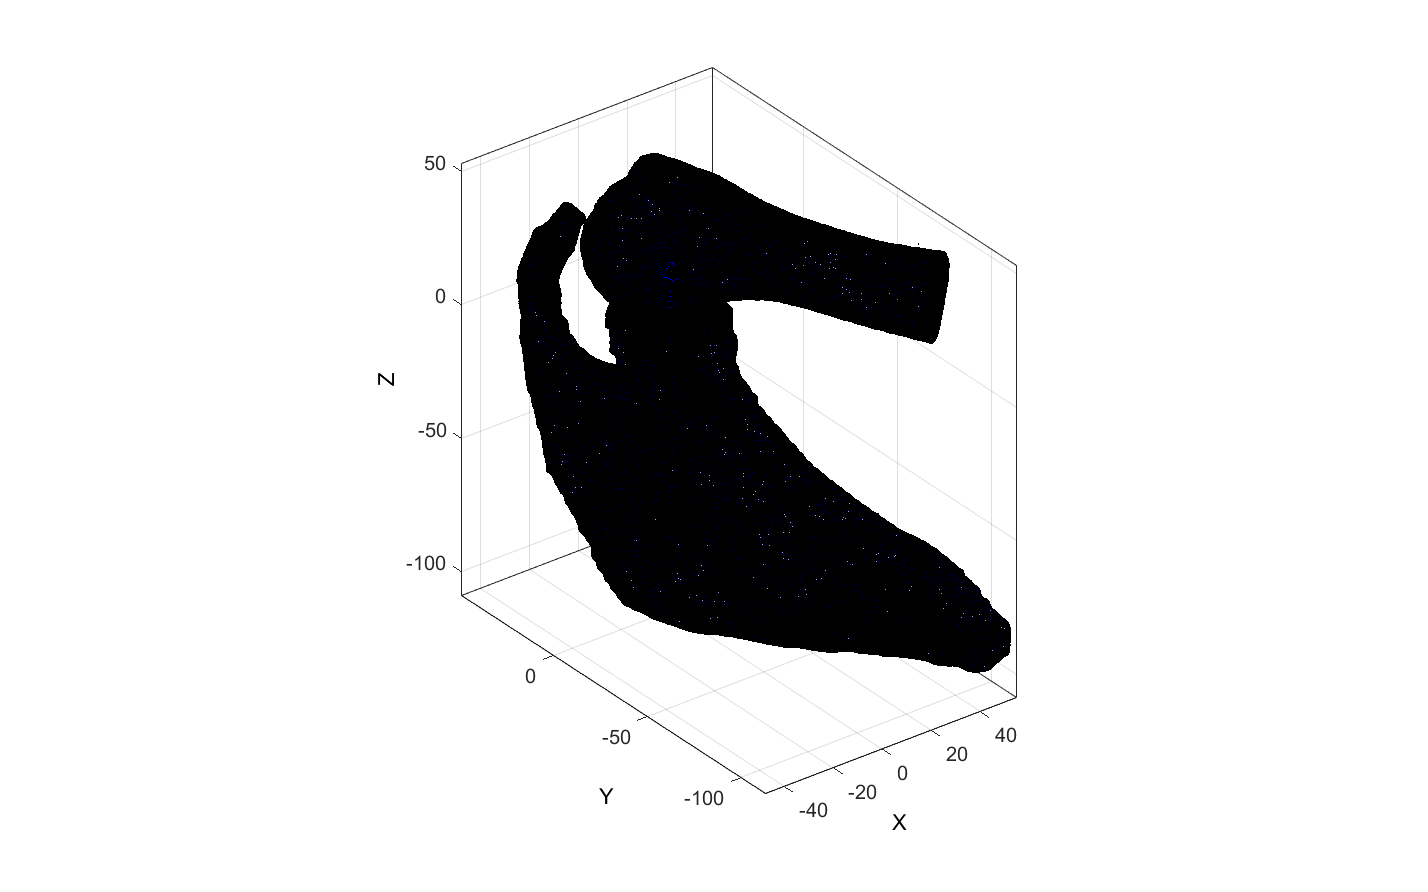

%Calculate the rotation between the glenoid plane vector and the worlds
%Z-axis vector
r = vrrotvec(planes.scapulaXYplane.normal,[0,0,1]);
%Get the rotation matrix for this alignment
m = vrrotvec2mat(r);

%Rotate and translate the points so they align at the origin and world XY
%axis. This also ensures that the other axes align with the other glenoid
%planes, however, they then need to be rotated 90 degrees around the Z-axis
%for these to align to the appropriate coordinate system.
%Set translation vector
transVec = (landmarks.deepGlenoid * m);
%Scapula vertices
scapulaV = (scapulaV * m) - transVec;
%Humerus vertices
humerusV = (humerusV * m) - transVec;
%Surface sphere vertices
surfaceV = (surfaceV * m) - transVec;
%Landmarks
fld = fieldnames(landmarks);
for ff = 1:length(fld)
    landmarks.(fld{ff}) = (landmarks.(fld{ff}) * m) - transVec;
end
clear ff

%Do the final 90 dgeree rotation around the Z axis
%Scapula vertices
scapulaV = (scapulaV * rotz(-90));
%Humerus vertices
humerusV = (humerusV * rotz(-90));
%Surface sphere vertices
surfaceV = (surfaceV * rotz(-90));
%Landmarks
for ff = 1:length(fld)
    landmarks.(fld{ff}) = (landmarks.(fld{ff}) * rotz(-90));
end
clear ff fld

%Visualise rotated data
cFigure;
gpatch(scapulaF,scapulaV,'b','k',0.2,1e-5);
hold on
gpatch(humerusF,humerusV,'b','k',0.2,1e-5);
axisGeom;
quiverVec([0,0,0],vecnormalize([1,0,0]),25,'r');
quiverVec([0,0,0],vecnormalize([0,1,0]),25,'g');
quiverVec([0,0,0],vecnormalize([0,0,1]),25,'b');


%Cleanup
clear r m

## Slice Up the Scapula

Use GIBBON's slicing tool to extract the glenoid face from the rest of the scapula. This will be sliced at a point 30mm back from the deep glenoid point along the normal of the plane fit to the glenoid surface. Prior to this though, so slicing along the X and Y axis directions is required to ensure extra bits of the scapula aren't included in the glenoid face.

%Specify the snap tolerance
snapTolerance = mean(patchEdgeLengths(scapulaF,scapulaV))/100;

%Cut above the glenoid

%Create the cutting plane by a normal vector
n = vecnormalize([0 1 0]); %Normal direction to plane

%Specify the point on the plane (25mm above the glenoid centre)
P = [0,25,0];

%Slicing the surface (note 3rd color data output is supressed)
[scapulaF_slice,scapulaV_slice,~,logicSide,scapulaE_slice] = ...
    triSurfSlice(scapulaF,scapulaV,[],P,n,snapTolerance);

%Keep only part below the plane and clean up
[scapulaF_slice,scapulaV_slice,indFix] = patchCleanUnused(scapulaF_slice(logicSide,:),scapulaV_slice);
scapulaE_slice = indFix(scapulaE_slice);

Remove the back side of the scapula

%Create the cutting plane by a normal vector
n = vecnormalize([-1 0 0]); %Normal direction to plane

%Specify the point on the plane (17mm back from the glenoid centre)
P = [-17,0,0];

%Slicing the surface (note 3rd color data output is supressed)
[scapulaF_slice,scapulaV_slice,~,logicSide,scapulaE_slice] = ...
    triSurfSlice(scapulaF_slice,scapulaV_slice,[],P,n,snapTolerance);

%Keep only part below the plane and clean up
[scapulaF_slice,scapulaV_slice,indFix] = patchCleanUnused(scapulaF_slice(logicSide,:),scapulaV_slice);
scapulaE_slice = indFix(scapulaE_slice);

Lastly, grab the actual glenoid surface.

%Create the cutting plane by a normal vector
n = vecnormalize([0 0 -1]); %Normal direction to plane

%Specify the point on the plane (30mm back from the glenoid face)
P = [0,0,-3];

%Slicing the surface (note 3rd color data output is supressed)
[scapulaF_slice,scapulaV_slice,~,logicSide,scapulaE_slice] = ...
    triSurfSlice(scapulaF_slice,scapulaV_slice,[],P,n,snapTolerance);

%Keep only part below the plane and clean up
[scapulaF_slice,scapulaV_slice,indFix] = patchCleanUnused(scapulaF_slice(logicSide,:),scapulaV_slice);
scapulaE_slice = indFix(scapulaE_slice);

Visualise the kept piece

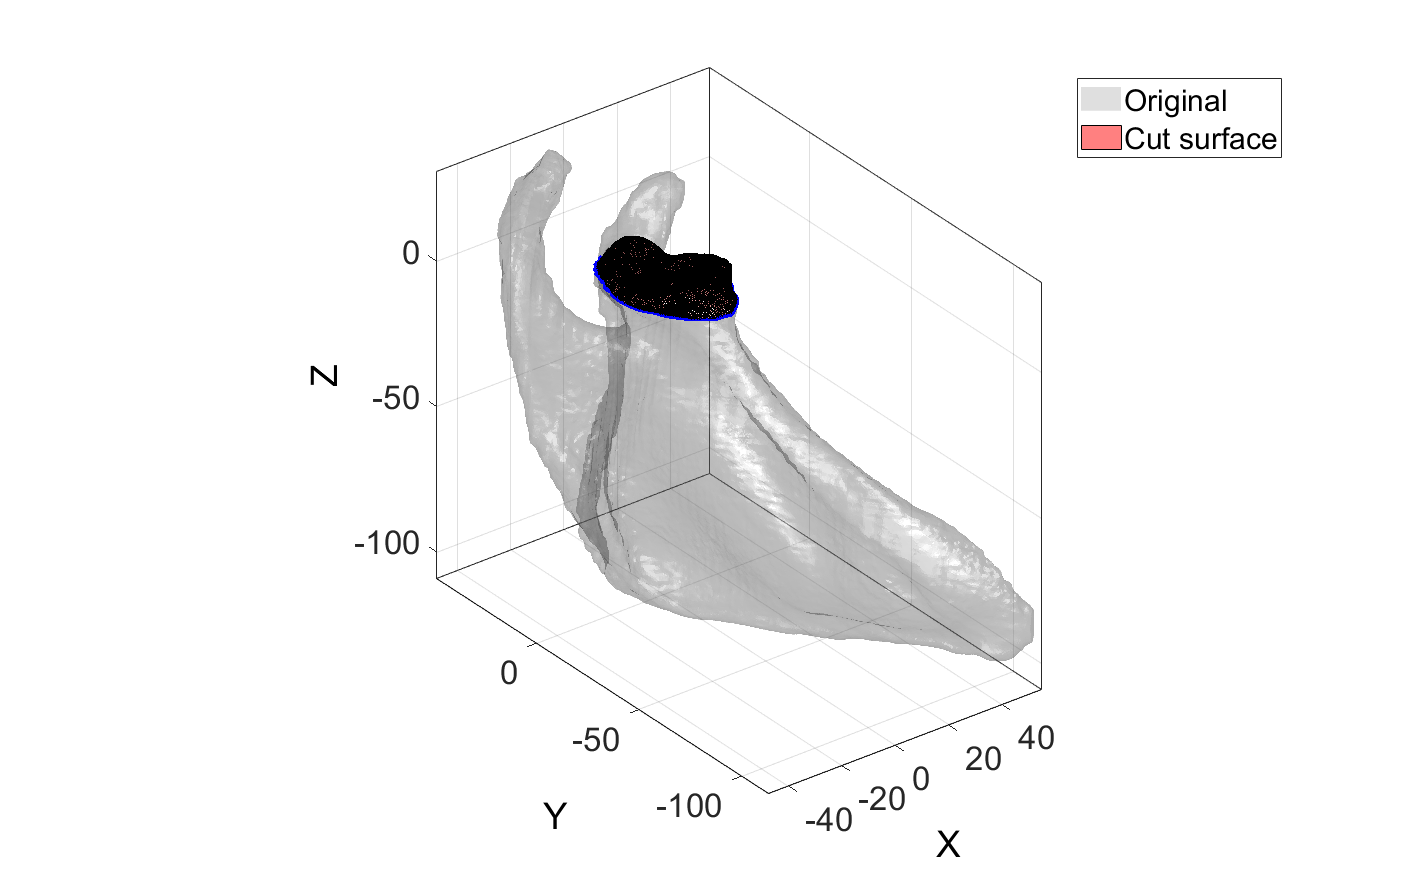

%Visualise kept piece
cFigure; hold on;
hp1 = gpatch(scapulaF,scapulaV,'kw','none',0.25);
hp2 = gpatch(scapulaF_slice,scapulaV_slice,'rw','k',1);
gpatch(scapulaE_slice,scapulaV_slice,'none','b',1,3);
legend([hp1 hp2],{'Original','Cut surface'})
axisGeom; axis manual; camlight headligth;
colormap gjet;
set(gca,'FontSize',fontSize);

***TODO: There are likely some sharp triangle edges at the cuts that should be smoothed out. Also it will be necessray to add a backing surface to the cuts that can be used to fix as a boundary surface.***

## Visualise the Landmarks on the Sliced Glenoid

This next step simply provides a visualisation to check that all of the landmarks are appropriately positioned on the rotated and sliced glenoid.

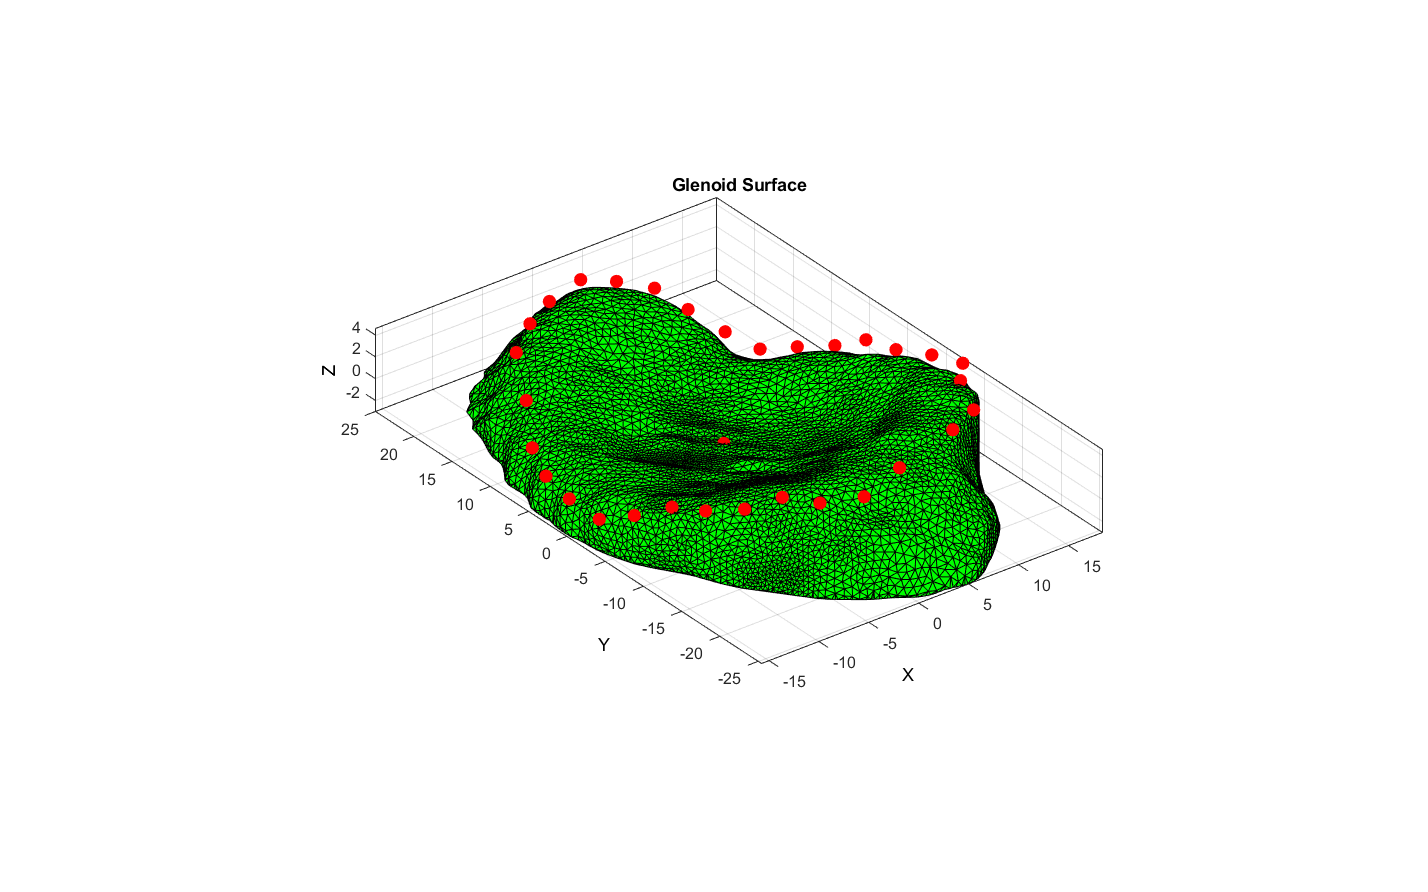

%Set a new glenoid vairable to call easier
glenoidV = scapulaV_slice;
glenoidF = scapulaF_slice;
glenoidE = scapulaE_slice;

%Visualise the cut glenoid and its associated landmarks
cFigure; hold on;
title('Glenoid Surface','FontSize',fontSize);
%Plot glenoid surface
gpatch(glenoidF,glenoidV,'g','k',1);
axisGeom(gca,12);
%Plot deep glenoid landmark
scatter3(landmarks.deepGlenoid(1),...
    landmarks.deepGlenoid(2),...
    landmarks.deepGlenoid(3),100,'r','filled');
%Plot glenoid rim points
for gg = 1:length(glenoidRimLabels)
    scatter3(landmarks.(glenoidRimLabels{gg})(1),...
        landmarks.(glenoidRimLabels{gg})(2),...
        landmarks.(glenoidRimLabels{gg})(3),100,'r','filled');
end

clear gg

Note that the above landmarks for the glenoid rim don't naturally sit on the surface. There is therefore a need to identify the closest vertices to these for appropriate meshing of the cartilage (if we use this method - see next section).

## Use the Glenoid Surface to Create Cartilage

In 3matic, faces approximating the glenoid surface were selected and exported as their own surface. We can project these in a way that creates cartilage. The following section tests out some methods relating to this.

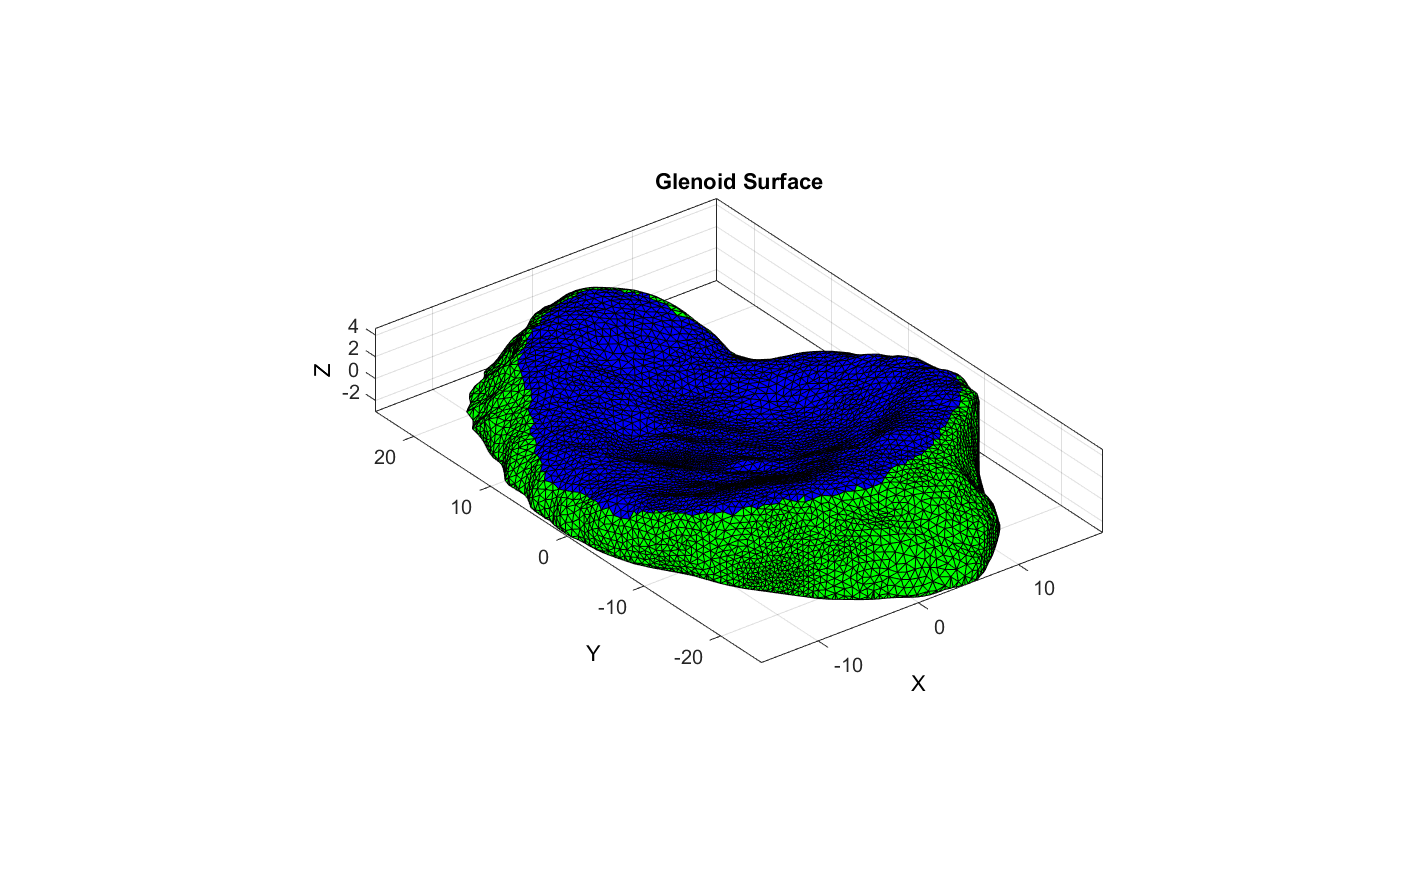

%Visualise the cut glenoid surface and the approximation of the face
cFigure; hold on;
title('Glenoid Surface','FontSize',fontSize);
%Plot glenoid surface
gpatch(glenoidF,glenoidV,'g','k',1);
axisGeom;
%Plot approximated surface
gpatch(surfaceF,surfaceV,'b','k',1);

The edges of these are obviously not smooth as they are based on brush mark of the faces. We could try out smoothing on this before trying to loft the cartilage surface.

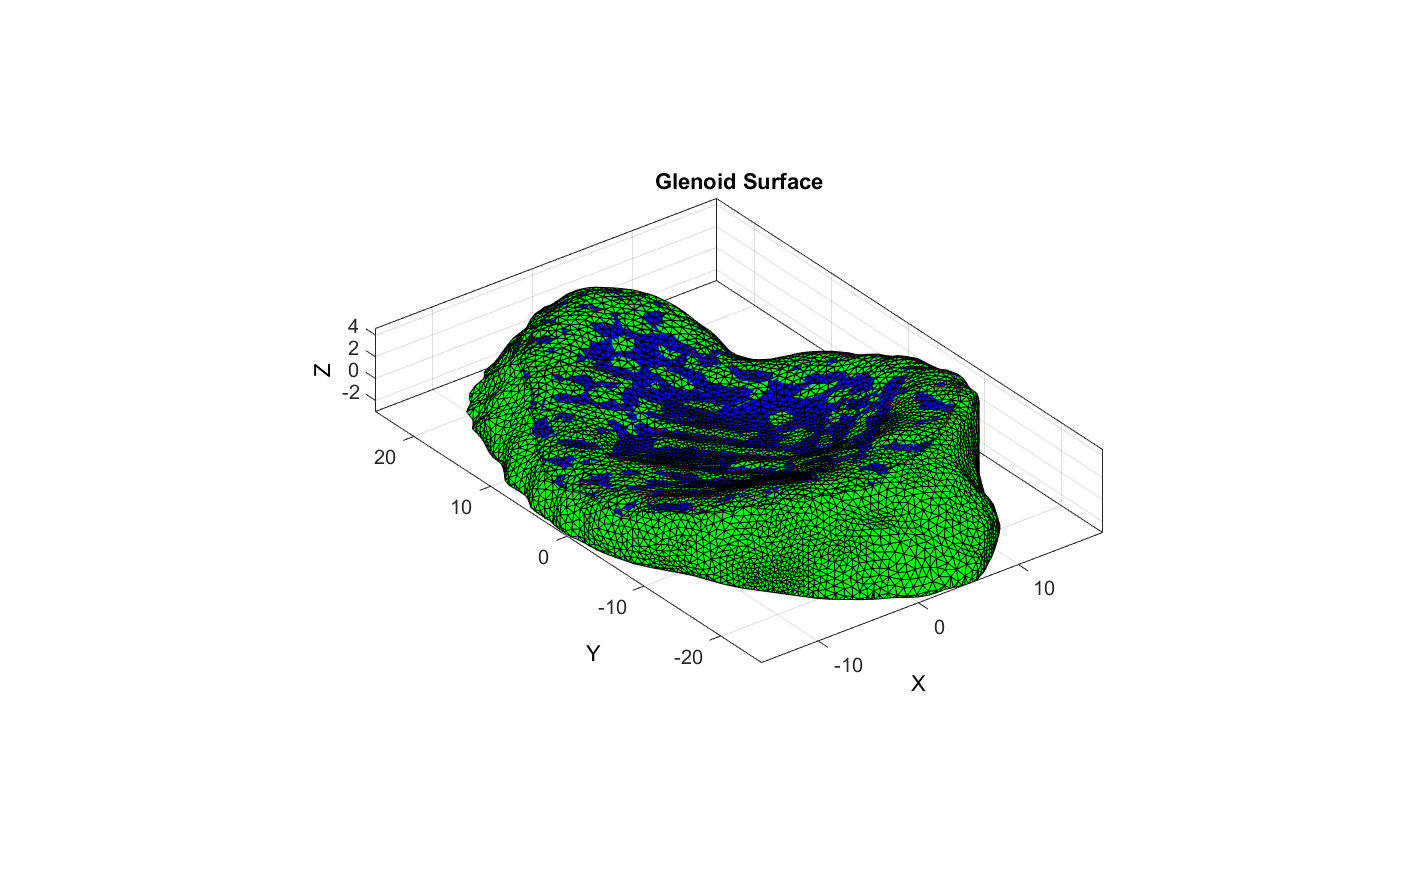

%Set methods for laplacian smoothing
cPar.n = 1; %Number of iterations
cPar.Method = 'LAP'; %Smooth method

%Smooth surface
[surfaceSmoothV] = patchSmooth(surfaceF,surfaceV,[],cPar);

%Examine smoothed surface
cFigure; hold on;
title('Glenoid Surface','FontSize',fontSize);
%Plot glenoid surface
gpatch(glenoidF,glenoidV,'g','k',1);
axisGeom;
%Plot approximated surface
gpatch(surfaceF,surfaceSmoothV,'b','k',1);

This sort of smooths out the surface, but potentially alters its position. A better option may be to loft it to a smoothed approximation of the surface. This wouldn't change the external loft position to much, but just provide a smoothed edge.

We can still use the self triangulate boundary function to create a starting loft section.

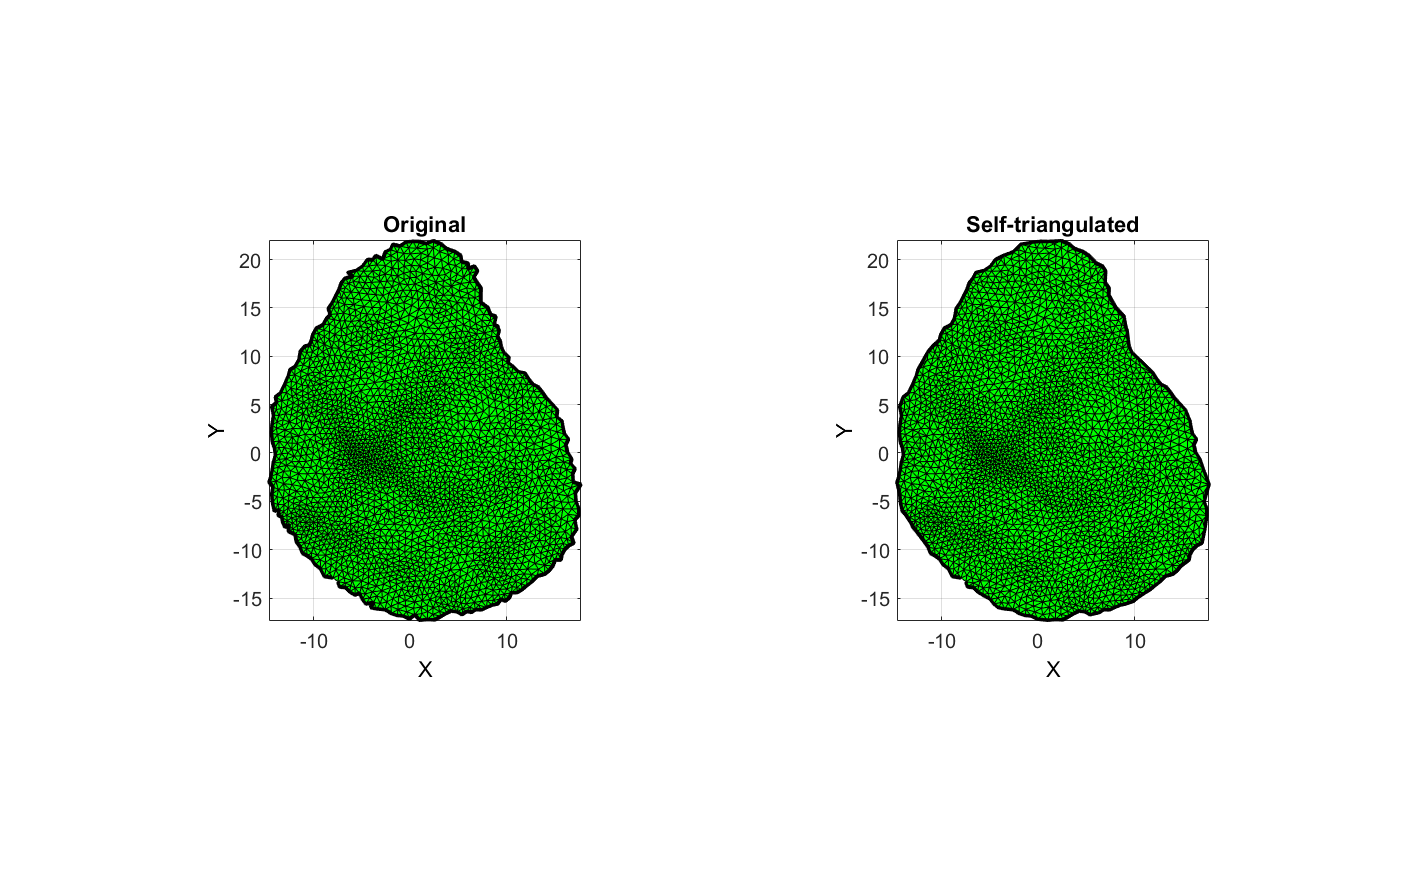

%Get the boundary points
cartilageBaseEb = patchBoundary(surfaceF,surfaceV);
cartilageBaseBC = edgeListToCurve(cartilageBaseEb);
cartilageBaseBC = cartilageBaseBC(1:end-1)'; %Start=End for closed curve so remove double entry

%Set parameters
angleThreshold = (140/180)*pi;
isClosedPath = 1;
[surfaceSmoothF,surfaceSmoothV,surfaceSmoothBC] = triSurfSelfTriangulateBoundary(surfaceF,surfaceV,cartilageBaseBC,angleThreshold,isClosedPath);

%Visualise results
cFigure;
subplot(1,2,1); hold on;
title('Original');
gpatch(surfaceF,surfaceV,'g');
plotV(surfaceV(indBoundaryCurve,:),'k-','LineWidth',3);
axisGeom; view(2);

subplot(1,2,2); hold on;
title('Self-triangulated');
gpatch(surfaceSmoothF,surfaceSmoothV,'g');
plotV(surfaceSmoothV(surfaceSmoothBC,:),'k-','LineWidth',3);
axisGeom; view(2);

The above does a pretty good job of smoothing the surface. Increasing the angle threshold anymore results in issues with the mesh.

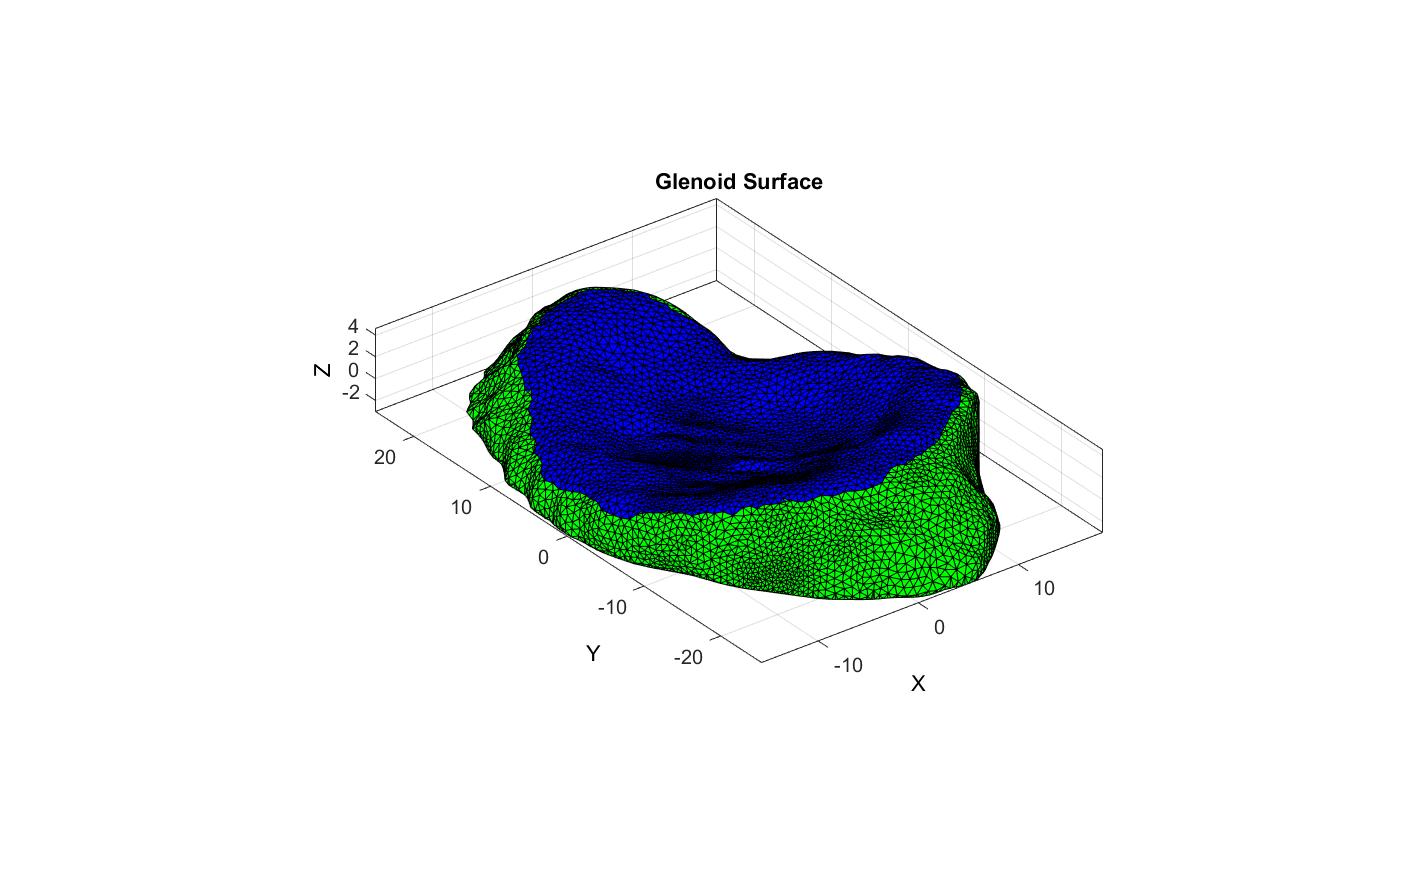

%Visualise on original glenoid
cFigure; hold on;
title('Glenoid Surface','FontSize',fontSize);
%Plot glenoid surface
gpatch(glenoidF,glenoidV,'g','k',1);
axisGeom;
%Plot approximated surface
gpatch(surfaceSmoothF,surfaceSmoothV,'b','k',1);

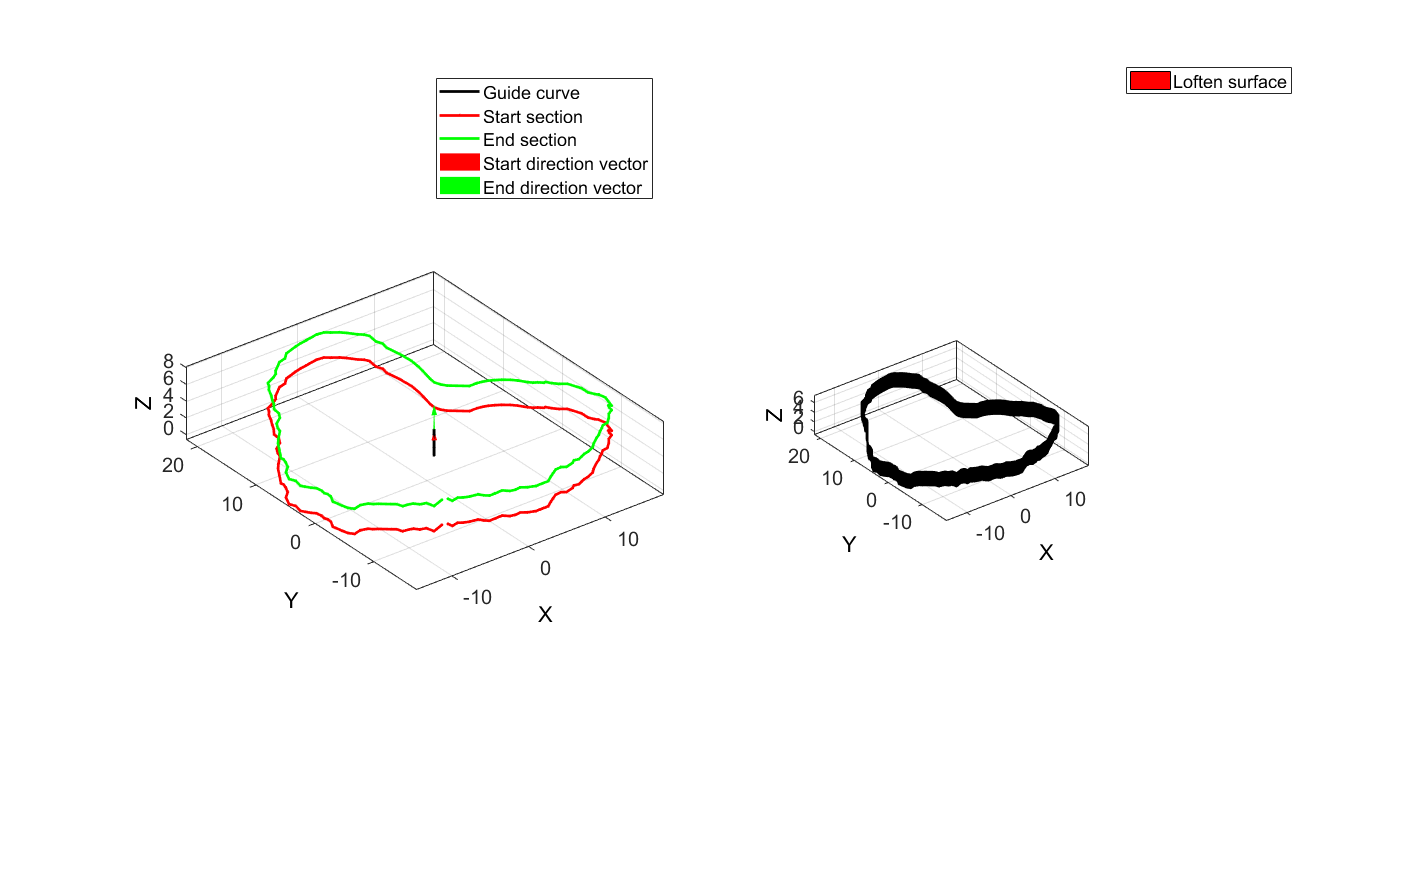

%Set start loft
startLoft = surfaceSmoothV(surfaceSmoothBC,:);

%Create the second sketch by adding the z-translation value
%For now we'll use a 'cartilage' thickness of 3mm, however this should be
%made specific by doing some digging around the gap between the humerus and
%scapula.
maxCartilageThickness = 3;
endLoft = [startLoft(:,1),startLoft(:,2),startLoft(:,3)+maxCartilageThickness];

%Create a guide curve (some default parameters)
%Should just be a straight line really...
numStepsCurve = maxCartilageThickness*10; %Number of steps for the curve
p1 = mean(startLoft,1); %First point
n1 = [0,0,1]; %First direction vector; z direction
p2 = mean(endLoft,1); %End point
n2 = [0,0,1]; %End direction vector; z direction
csapsSmoothPar = 1; %Cubic smoothening spline smoothening parameter
f = 0.05; %Extent of tangential nature to boundary curves, surface will remain approximately orthogonal to input curves for f*distance between curves
[Vg] = sweepCurveSmooth(p1,p2,n1,n2,numStepsCurve,csapsSmoothPar,f);

%Create the loft feature
[cartilageOuterF,cartilageOuterV] = sweepLoft(startLoft,endLoft,n1,n2,Vg);

%Visualise the loft feature
cFigure;
subplot(1,2,1);
hold on;
h(1)=plotV(Vg,'k.-','LineWidth',2);
h(2)=plotV(startLoft,'r.-','LineWidth',2);
h(3)=plotV(endLoft,'g.-','LineWidth',2);
h(4)=quiverVec(p1,n1,3,'r');
h(5)=quiverVec(p2,n2,3,'g');
legend(h,{'Guide curve','Start section','End section','Start direction vector','End direction vector'});
axisGeom;

subplot(1,2,2); hold on;
h = gpatch(cartilageOuterF,cartilageOuterV,'r','k',1);
axisGeom;
legend(h,{'Loften surface'});
camlight headlight

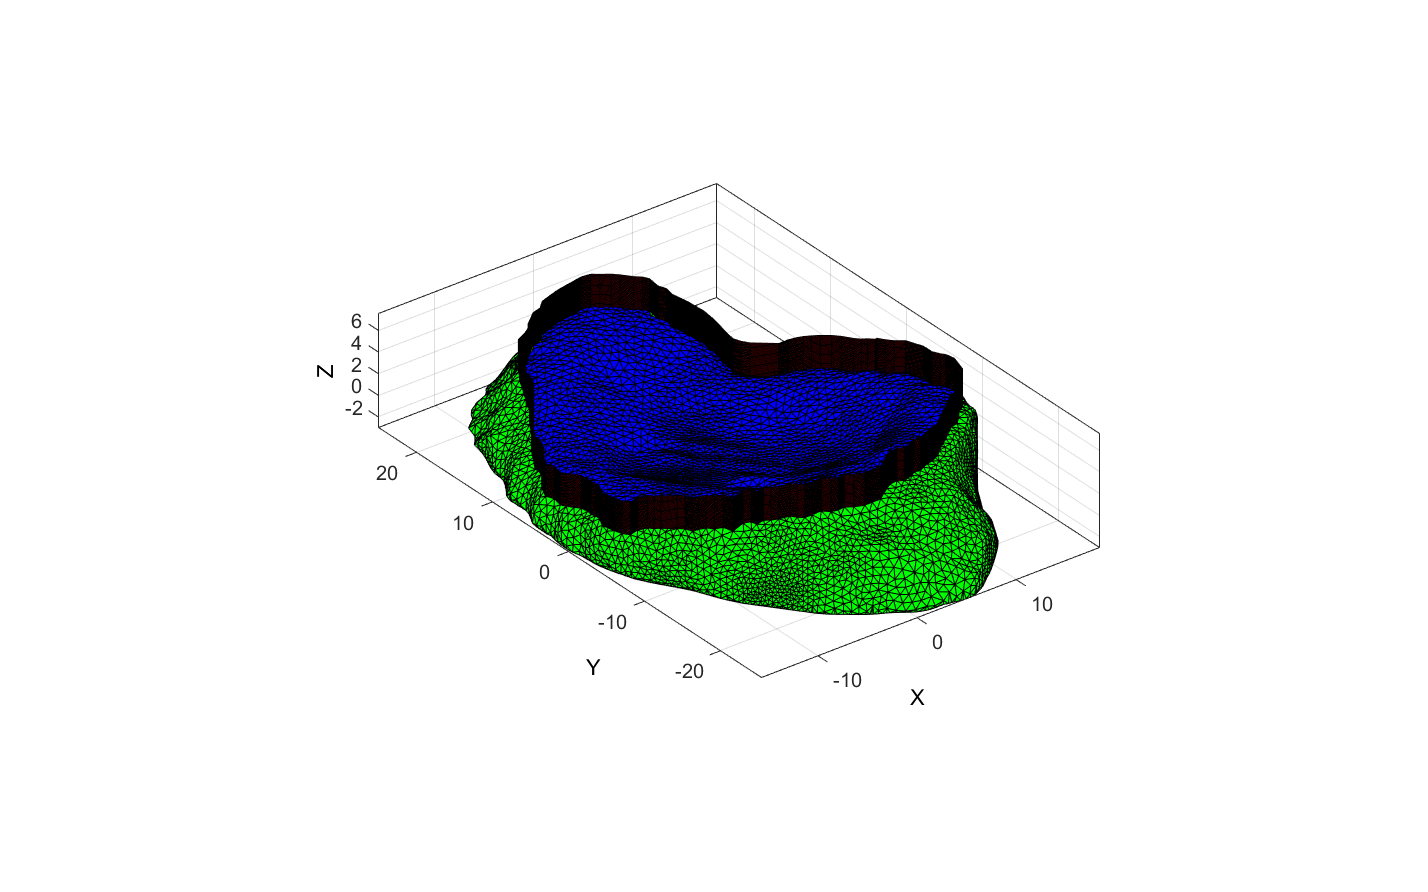


%Visualise the cartilage loft with the glenoid
cFigure; hold on;
%Plot glenoid surface
gpatch(glenoidF,glenoidV,'g','k',1);
axisGeom;
%Plot cartilgae loft
gpatch(surfaceSmoothF,surfaceSmoothV,'b','k',1);
%Plot the cartilage base
gpatch(cartilageOuterF,cartilageOuterV,'r','k',1);

This works pretty well, although could be smoother. This could be achieved by starting with a smoother starting base and boundary, or by lofting to a smoothed surface initially over a very small distance (and then do the big loft. There are still some minor inconsistencies with the cartilage base connecting with the edge, but the outer cartilage surface seems to connect pretty well to the glenoid surface.

The next step is to fix up the top bit. This might be tricky as the surface may not follow what we want. This could simply be solved by reusing the starting surface on top, and this would give it a constant thickness.

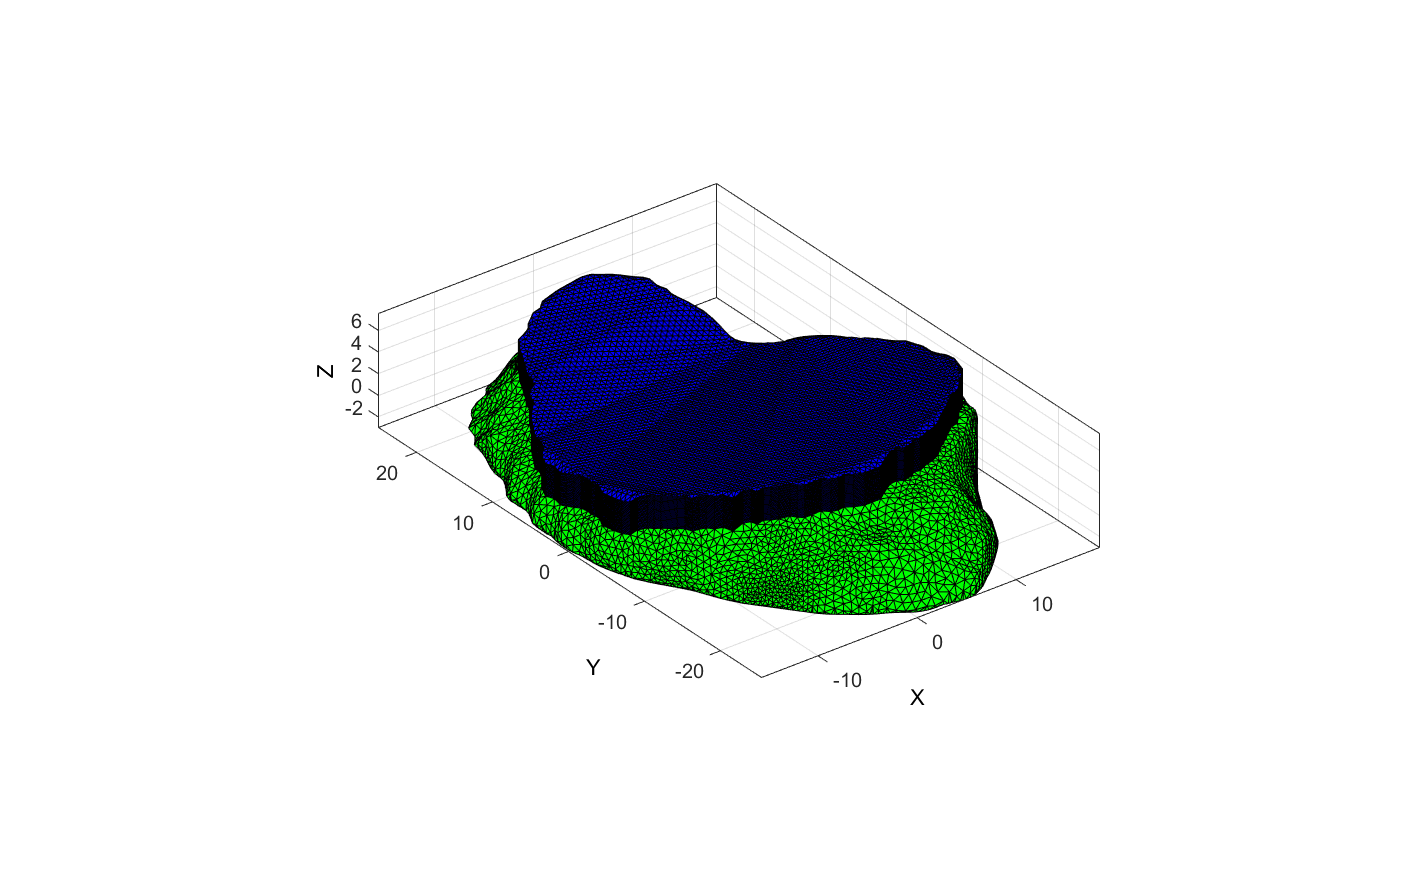

%Test out covering over the top
%Use the end loft as the region to fill

%Place in the region cell for the meshing procedure
regionCell = {endLoft};

%Defining a region and control parameters (See also |regionTriMesh2D|)
pointSpacing = 0.5; %Desired point spacing (half of bone meshes for now)
resampleCurveOpt = 1; %option for resampling the curve
interpMethod = 'linear'; %or 'natural'
[cartilageTopF,cartilageTopV] = regionTriMesh3D(regionCell,pointSpacing,resampleCurveOpt,interpMethod);

%Visualise the surfaces together
cFigure; hold on;
%Plot glenoid surface
gpatch(glenoidF,glenoidV,'g','k',1);
axisGeom;
%Plot cartilgae
gpatch(surfaceSmoothF,surfaceSmoothV,'b','k',1);
gpatch(cartilageOuterF,cartilageOuterV,'b','k',1);
gpatch(cartilageTopF,cartilageTopV,'b','k',1);

As with earlier comments, the cartilage ain't that smooth - but it is the best method so far. It may be best to generate a smooth approximation from the get go out of 3matic, that fits the surface well. This will avoid any mismatching issues and eliminate some approximate choices being made in this methodology. I'm not sure how well a non constant thickness approach will work with this, but the constant thickness is supported by the Buchler et al. study.

A smoother starting surface can be achieved by smoothing the boundary of the marekd triangles before extracting the surface. This may also allow the objects to be exported together (or still may need to do the separate surface) as it creates separate surfaces on the scapula object. Smaller triangles are inserted around the border to make it smooth.

## Identify Appropriate Glenoid Rim Points

As above, there is a need to identify where the closest vertices are to these glenoid rim points so that they match up on the surface. This can be done fairly easily by calculating the distance between all of the rim points to the vertices, and finding the minum one.

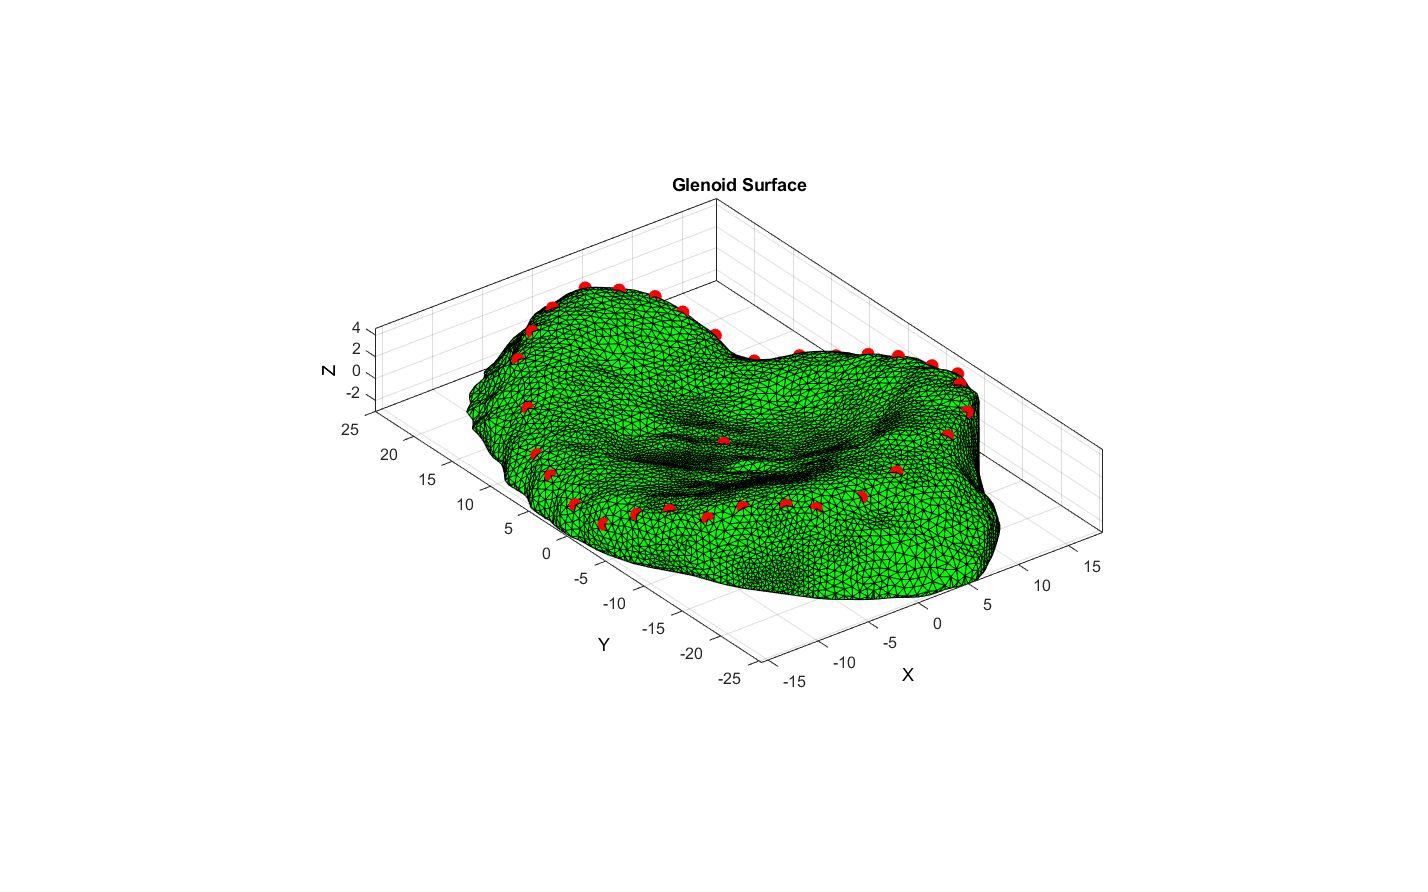

%Calculate nearest vertices to each glenoid rim point
for gg = 1:length(glenoidRimLabels)

    %Loop through glenoid vertices and calculate distances
    for vv = 1:length(glenoidV)
        %Specify points
        P1 = glenoidV(vv,:); P2 = landmarks.(glenoidRimLabels{gg})(1,:);
        distPoints(vv) = sqrt((P1(:,1)-P2(:,1)).^2+(P1(:,2)-P2(:,2)).^2+(P1(:,3)-P2(:,3)).^2);
        clear P1 P2
    end
    clear vv
    
    %Find the minimum distance
    minInd = find(distPoints == min(distPoints));
    
    %Replace the current glenoid rim point with the one from the glenoid
    %surface vertices
    landmarks.(glenoidRimLabels{gg})(1,:) = glenoidV(minInd,:);
    
    %Cleanup
    clear distPoints minInd

end
clear gg

%Visualise updated glenoid rim points on surface
cFigure; hold on;
title('Glenoid Surface','FontSize',fontSize);
%Plot glenoid surface
gpatch(glenoidF,glenoidV,'g','k',1);
axisGeom(gca,12);
%Plot deep glenoid landmark
scatter3(landmarks.deepGlenoid(1),...
    landmarks.deepGlenoid(2),...
    landmarks.deepGlenoid(3),100,'r','filled');
%Plot glenoid rim points
for gg = 1:length(glenoidRimLabels)
    scatter3(landmarks.(glenoidRimLabels{gg})(1),...
        landmarks.(glenoidRimLabels{gg})(2),...
        landmarks.(glenoidRimLabels{gg})(3),100,'r','filled');
end

These new points are OK, but the shape made by them could be smoother, so we can fit a nice smooth shape to these points and then match it back up to the glenoid rim.

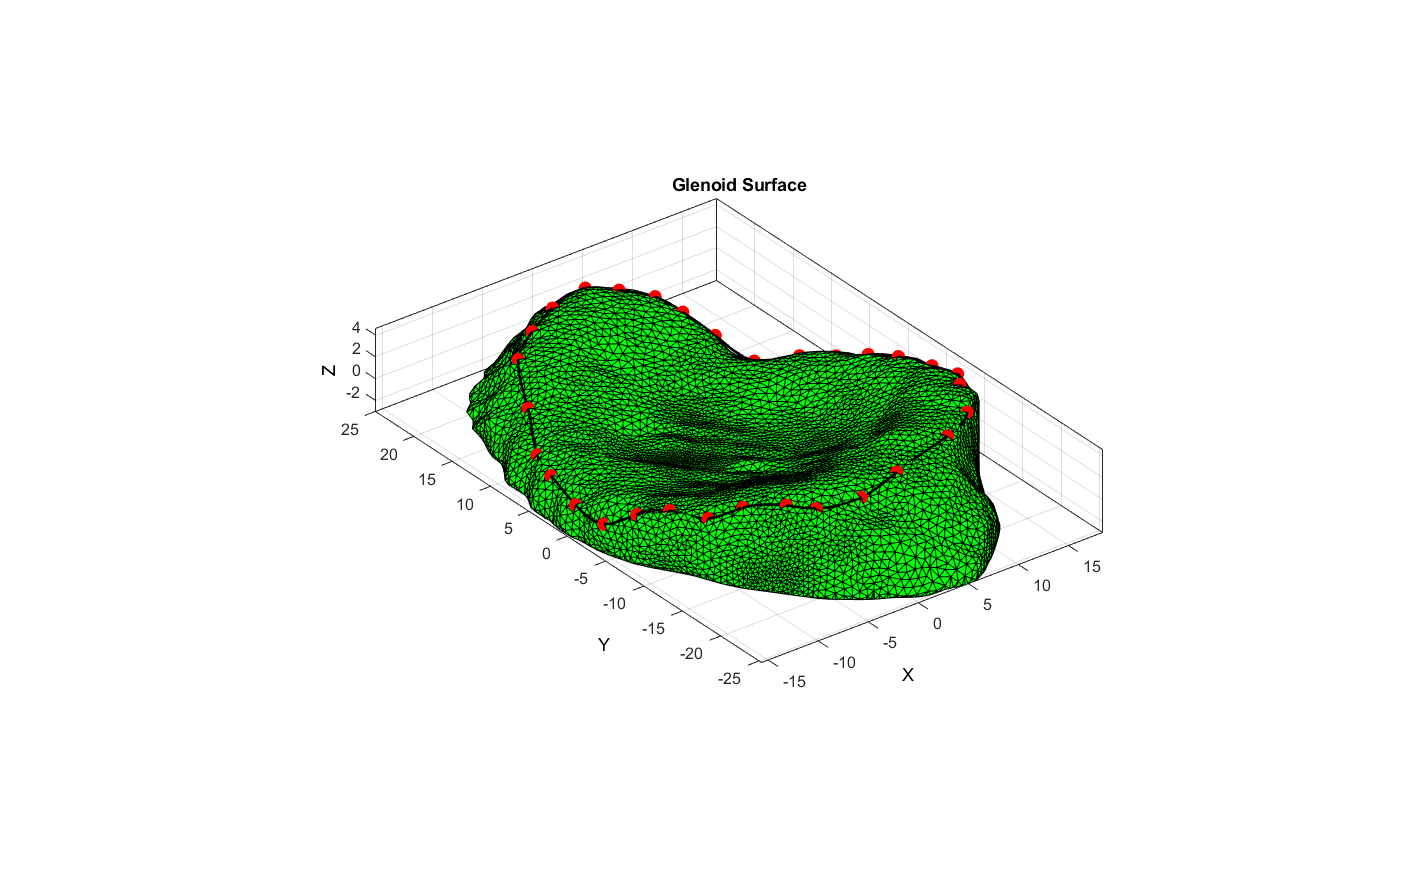

%Place the glenoid rim points into a single structure
%The points need to be placed in an appropriate order so that the smooth
%boundary is fit appropriately. This can be done by finding the angle
%between the origin of the glenoid to the XY points versus vertical, and
%then ordering these.
%For calculating angles, see: https://au.mathworks.com/matlabcentral/answers/486528-how-to-find-angle-between-two-lines
%Calculate angle
for gg = 1:length(glenoidRimLabels)
    if landmarks.(glenoidRimLabels{gg})(1) >= 0 && landmarks.(glenoidRimLabels{gg})(2) >= 0
        ang(gg,1) = atand(landmarks.(glenoidRimLabels{gg})(1)/landmarks.(glenoidRimLabels{gg})(2));
    elseif landmarks.(glenoidRimLabels{gg})(1) >= 0 && landmarks.(glenoidRimLabels{gg})(2) < 0
        ang(gg,1) = atand((landmarks.(glenoidRimLabels{gg})(2)*-1)/landmarks.(glenoidRimLabels{gg})(1)) + 90;
    elseif landmarks.(glenoidRimLabels{gg})(1) < 0 && landmarks.(glenoidRimLabels{gg})(2) < 0
        ang(gg,1) = atand((landmarks.(glenoidRimLabels{gg})(1)*-1)/(landmarks.(glenoidRimLabels{gg})(2)*-1)) + 180;
    elseif landmarks.(glenoidRimLabels{gg})(1) < 0 && landmarks.(glenoidRimLabels{gg})(2) >= 0
        ang(gg,1) = atand(landmarks.(glenoidRimLabels{gg})(2)/(landmarks.(glenoidRimLabels{gg})(1)*-1)) + 270;
    end
    ang(gg,2) = gg;
end
clear gg
%Sort the angles and the indices
sortAng = sortrows(ang,1);
    
%Get the ordered XYZ points of the glenoid rim points
for aa = 1:length(sortAng)
    xyzGlenoidPoints(aa,:) = landmarks.(glenoidRimLabels{sortAng(aa,2)})(1,:);
end
clear aa

%Visualise and get a smoothed boundary
cFigure; hold on;
title('Glenoid Surface','FontSize',fontSize);
%Plot glenoid surface
gpatch(glenoidF,glenoidV,'g','k',1);
axisGeom(gca,12);
%Plot glenoid rim points
for gg = 1:length(glenoidRimLabels)
    scatter3(landmarks.(glenoidRimLabels{gg})(1),...
        landmarks.(glenoidRimLabels{gg})(2),...
        landmarks.(glenoidRimLabels{gg})(3),100,'r','filled');
end
%Get and plot smoothed boundary
xyzGlenoidPoints = xyzGlenoidPoints';
smoothedGlenoidBoundary = fnplt(cscvn(xyzGlenoidPoints(:,[1:end 1])),'r',2);
plot3(smoothedGlenoidBoundary(1,:),...
    smoothedGlenoidBoundary(2,:),...
    smoothedGlenoidBoundary(3,:),'k-','LineWidth',2)

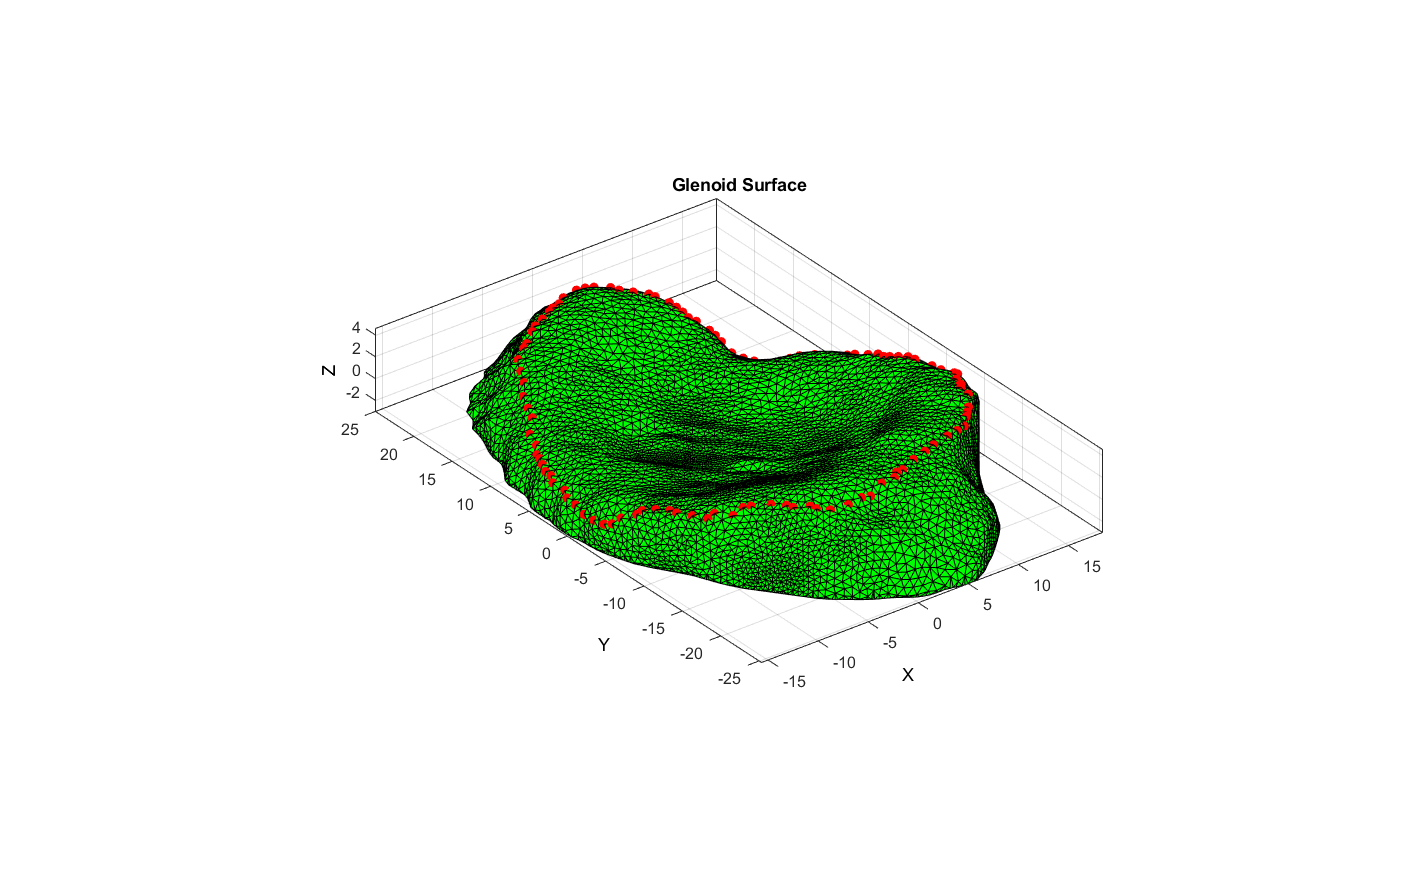

%Transpose the new smoothed points so they are in XYZ form
smoothedGlenoidBoundary = smoothedGlenoidBoundary';

%Re-run the same process as before in identifying the closest vertices to
%the smoothed boundary points to ensure they lie on the glenoid surface
%Calculate nearest vertices to each glenoid rim point
for gg = 1:length(smoothedGlenoidBoundary)

    %Loop through glenoid vertices and calculate distances
    for vv = 1:length(glenoidV)
        %Specify points
        P1 = glenoidV(vv,:); P2 = smoothedGlenoidBoundary(gg,:);
        distPoints(vv) = sqrt((P1(:,1)-P2(:,1)).^2+(P1(:,2)-P2(:,2)).^2+(P1(:,3)-P2(:,3)).^2);
        clear P1 P2
    end
    clear vv
    
    %Find the minimum distance
    minInd = find(distPoints == min(distPoints));
    
    %Replace the current glenoid rim point with the one from the glenoid
    %surface vertices
    smoothedGlenoidBoundary(gg,:) = glenoidV(minInd,:);
    
    %Cleanup
    clear distPoints minInd

end
clear gg

%Replot points to have a look
cFigure; hold on;
title('Glenoid Surface','FontSize',fontSize);
%Plot glenoid surface
gpatch(glenoidF,glenoidV,'g','k',1);
axisGeom(gca,12);
%Plot glenoid rim points
for gg = 1:length(smoothedGlenoidBoundary)
    scatter3(smoothedGlenoidBoundary(gg,1),...
        smoothedGlenoidBoundary(gg,2),...
        smoothedGlenoidBoundary(gg,3),50,'r','filled');
end

## Use the Surface Sphere to get a Good Cartilage Surface

We have some boundary points that specfy the glenoid rim edge, and a smooth sphere fitted to this surface. We can use the glenoid rim boundary to only extract the faces of the surface sphere that fit within this boundary. From this we hopefull have a smooth surface that sits close to the glenoid face surface.

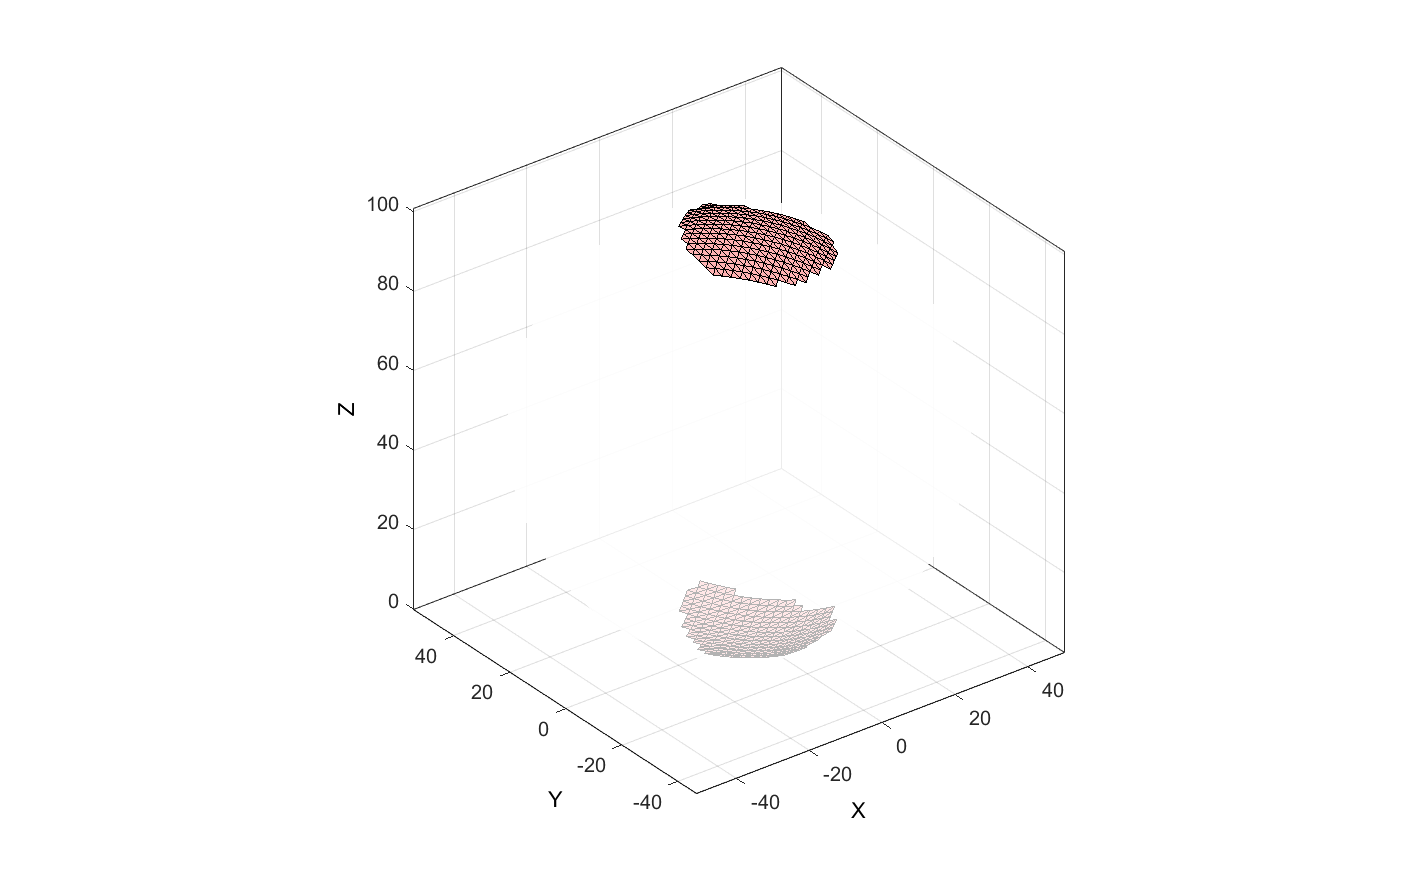

%Create a polyshape based on the smoothed points
polyin = polyshape(smoothedGlenoidBoundary(:,1),smoothedGlenoidBoundary(:,2));

%Determine which sphere vertices are within the smoothed boundary XY points
inFace = isinterior(polyin,surfaceV(:,1),surfaceV(:,2));

%Plot those that are in and out with green and red
plot(polyin)
hold on
scatter(surfaceV(inFace,1),surfaceV(inFace,2),2,'g','filled')
scatter(surfaceV(~inFace,1),surfaceV(~inFace,2),2,'r','filled')

%Create a detached mesh set based on whether to keep the vertices or not
logicKeep = all(inFace(surfaceF),2);
[glenoidFaceF,glenoidFaceV] = patchCleanUnused(surfaceF(logicKeep,:),surfaceV);

%Visualise new mesh
cFigure; hold on
gpatch(surfaceF,surfaceV,'w','none',0.7);
gpatch(glenoidFaceF,glenoidFaceV,'r','k',1);
axisGeom;

The above results in a face on the bottom and the top of the sphere, we only want the bottom one to use as the glenoid cartilage starting surface.

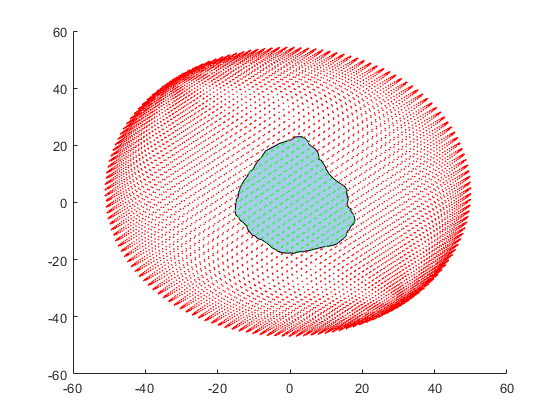

%Group the two sets of faces that were extracted to only grab the ones
%close to the surface
optionStruct.outputType = 'label';
glenoidFaceG = tesgroup(glenoidFaceF,optionStruct);

%Visualise grouped faces
cFigure;

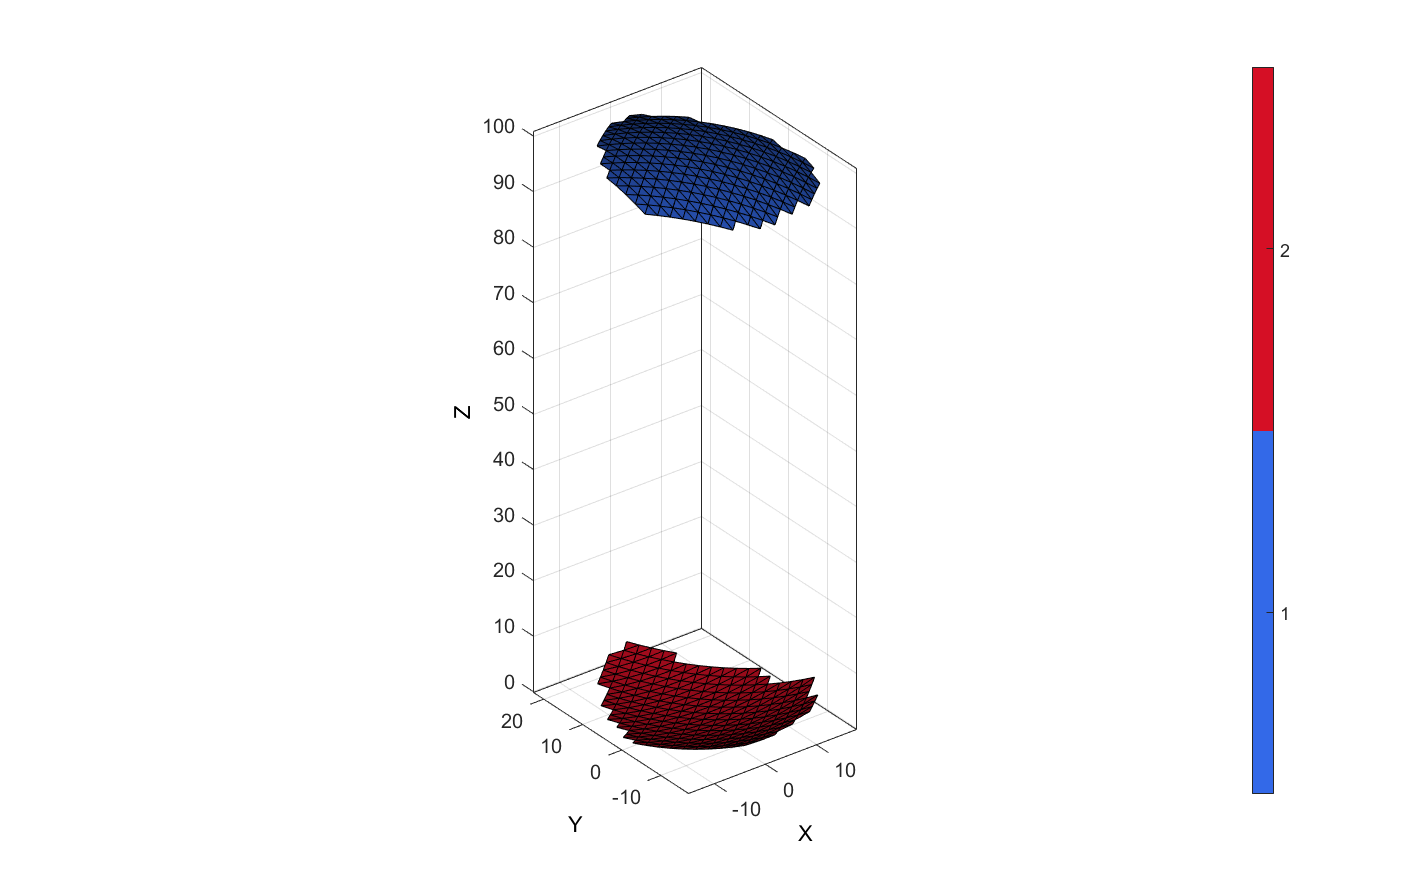

gpatch(glenoidFaceF,glenoidFaceV,glenoidFaceG,'k',1);
axisGeom;
camlight headlight;
colormap gjet; icolorbar;

The above results in the labels of 2 being applied to the bottom part of the sphere. Use this to extract the relevant faces and vertices

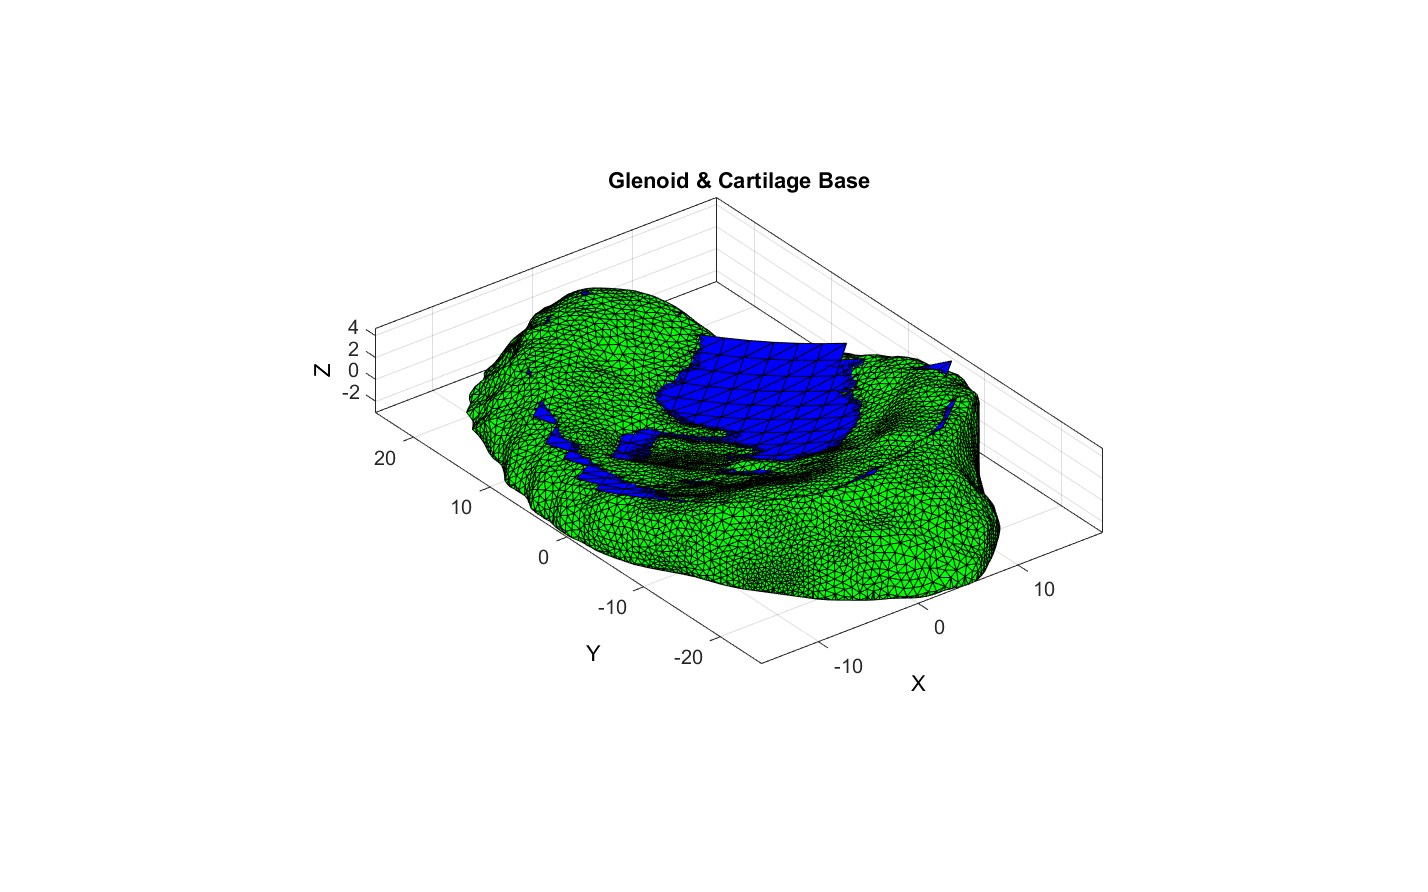

%Extract relevant faces and vertices for cartilage base
logicBase = glenoidFaceG == 2;
[cartilageBaseF,cartilageBaseV] = patchCleanUnused(glenoidFaceF(logicBase,:),glenoidFaceV);

%Visualise with glenoid
cFigure; hold on;
title('Glenoid & Cartilage Base','FontSize',fontSize);
gpatch(glenoidF,glenoidV,'g','k',1);
gpatch(cartilageBaseF,cartilageBaseV,'b','k',1);
axisGeom;

Note that the above cartilage base seems to project into the glenoid. Don't know what the effect of this will be, but so far this is the best base fitting the surface that we've got.

***TODO: The mesh of the sphere could be finer to potentially get a smoother edge.***

## Extend Along the Smoothed Glenoid Base

Now that we have a potentially appropriate boundary, we can extend out from the glenoid face to create a cartilage structure. This could be done using the new patchExtend method, or by using the earlier loft feature of the GIBBON toolbox.

Both could be useful, but given this example will simply extend along the Z axis by a certain amount, the sweepLoft function can do the job fine.

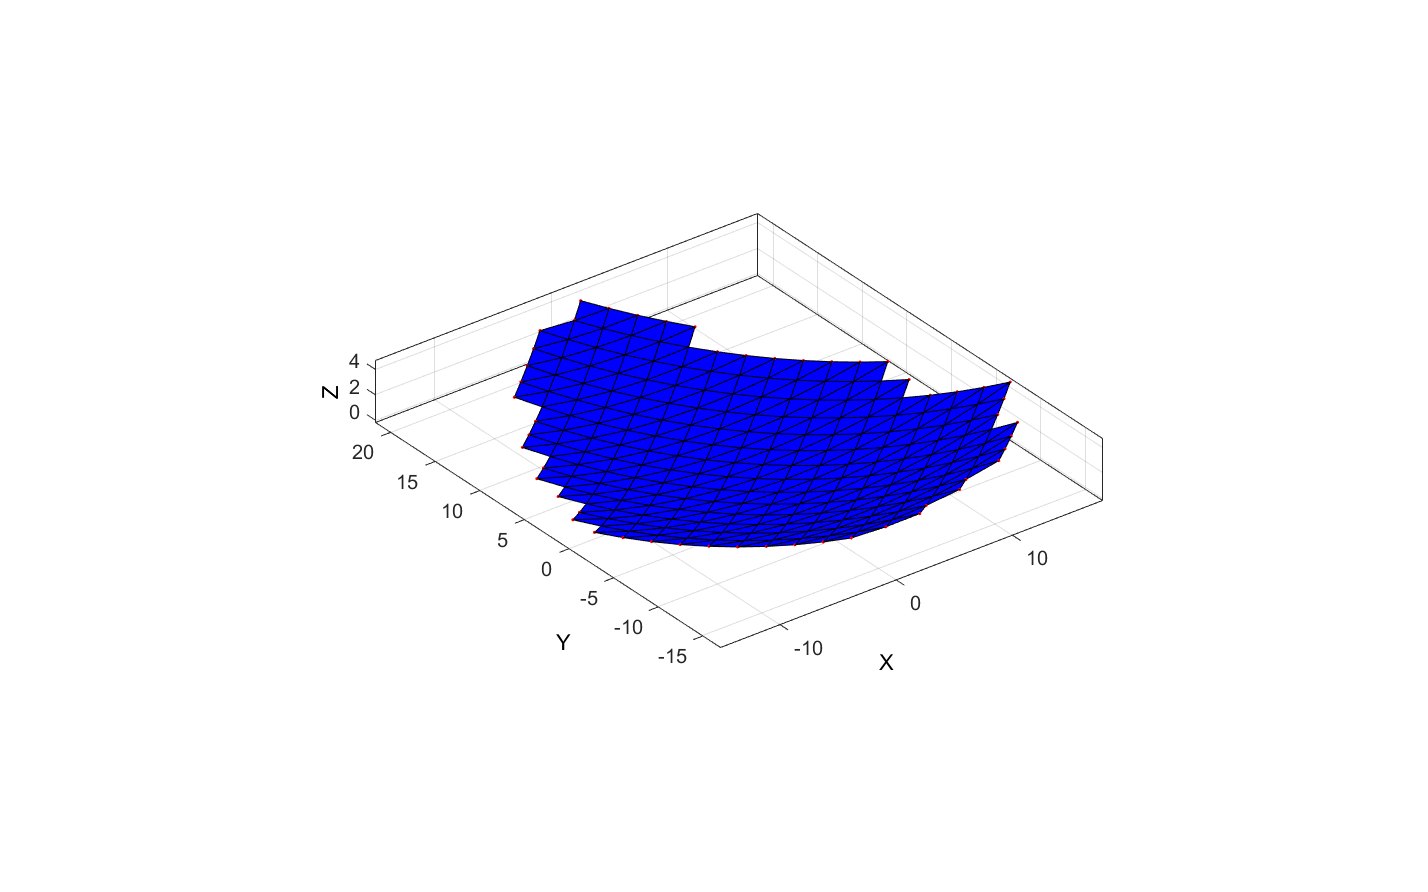

%Get the edge points of the mesh to create a sketch for the loft start
cartilageBaseE = patchBoundary(cartilageBaseF,cartilageBaseV);
cartilageBaseVE = patchCentre(cartilageBaseE,cartilageBaseV); %Edge centre coordinates

%Get the XY boundary points
%This is needed later to avoid errors with the evenly sampled curve
k = boundary(cartilageBaseV(:,1),cartilageBaseV(:,2),1);
Vbnd(:,1) = cartilageBaseV(k,1);
Vbnd(:,2) = cartilageBaseV(k,2);
Vbnd(:,3) = cartilageBaseV(k,3);
% Vbnd = Vbnd(1:end-1,:); %remove the last point for discontinuity

%Visualise boundary points
cFigure; hold on;
gpatch(cartilageBaseF,cartilageBaseV,'b','k',1);
axisGeom;
scatter3(Vbnd(:,1),Vbnd(:,2),Vbnd(:,3),'r.')

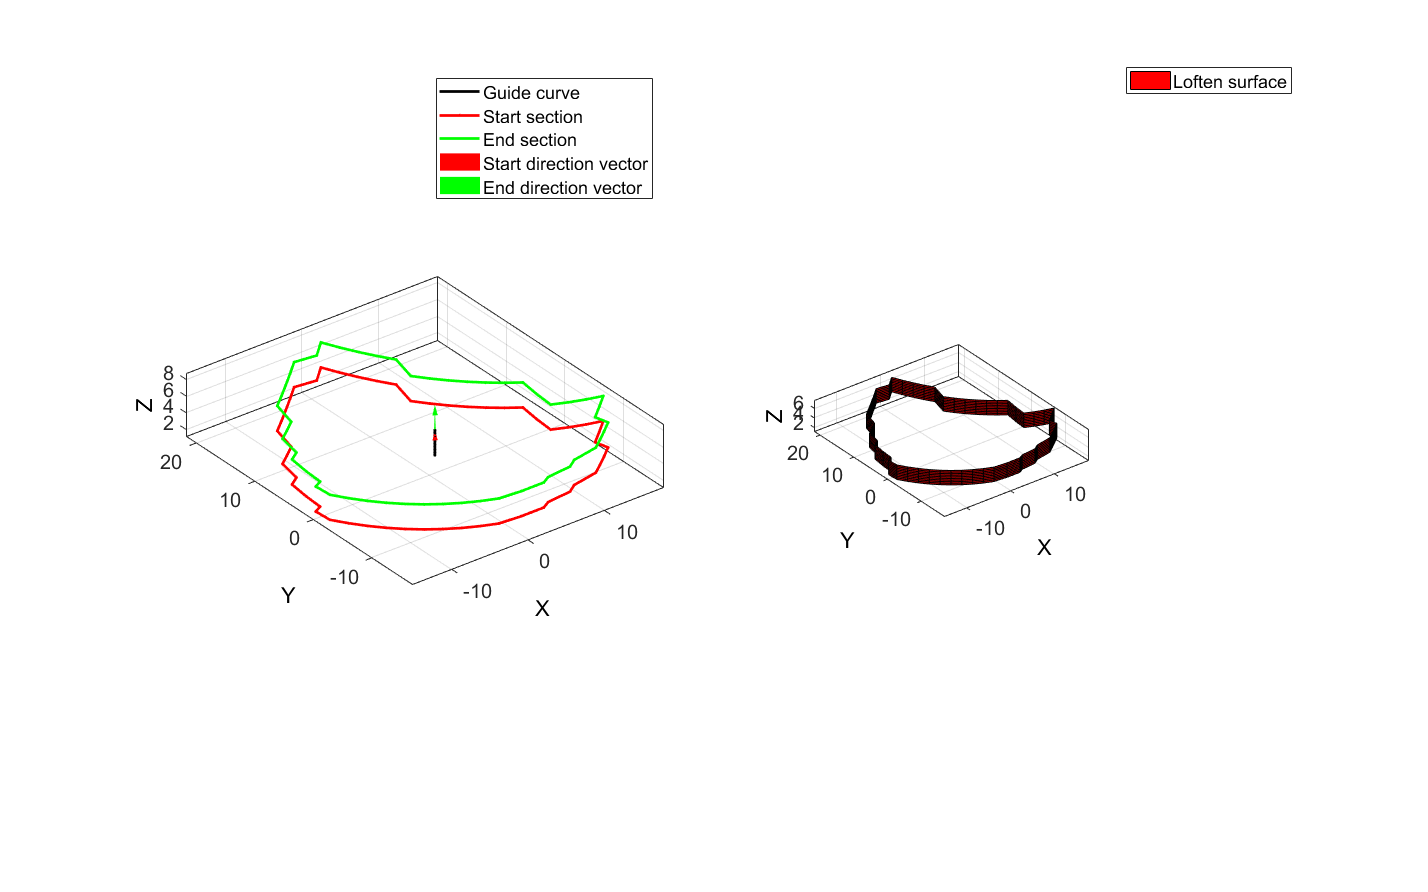


%Set start loft
startLoft = Vbnd;
% %Smooth the boundary to a large number of points for clean-ish edges
% %Set back to the start glenoid loft variable
% startLoft = evenlySampleCurve(Vbnd,1000,'pchip',1);
clear k Vbnd

%Create the second sketch by adding the z-translation value
%For now we'll use a 'cartilage' thickness of 3mm, however this should be
%made specific by doing some digging around the gap between the humerus and
%scapula.
maxCartilageThickness = 3;
endLoft = [startLoft(:,1),startLoft(:,2),startLoft(:,3)+maxCartilageThickness];

%Create a guide curve (some default parameters)
%Should just be a straight line really...
numStepsCurve = 10; %Number of steps for the curve
p1 = mean(startLoft,1); %First point
n1 = [0,0,1]; %First direction vector; z direction
p2 = mean(endLoft,1); %End point
n2 = [0,0,1]; %End direction vector; z direction
csapsSmoothPar = 1; %Cubic smoothening spline smoothening parameter
f = 0.05; %Extent of tangential nature to boundary curves, surface will remain approximately orthogonal to input curves for f*distance between curves
[Vg] = sweepCurveSmooth(p1,p2,n1,n2,numStepsCurve,csapsSmoothPar,f);

%Create the loft feature
[cartilageOuterF,cartilageOuterV] = sweepLoft(startLoft,endLoft,n1,n2,Vg);

%Visualise the loft feature
cFigure;
subplot(1,2,1);
hold on;
h(1)=plotV(Vg,'k.-','LineWidth',2);
h(2)=plotV(startLoft,'r.-','LineWidth',2);
h(3)=plotV(endLoft,'g.-','LineWidth',2);
h(4)=quiverVec(p1,n1,3,'r');
h(5)=quiverVec(p2,n2,3,'g');
legend(h,{'Guide curve','Start section','End section','Start direction vector','End direction vector'});
axisGeom;

subplot(1,2,2); hold on;
h = gpatch(cartilageOuterF,cartilageOuterV,'r','k',1);
axisGeom;
legend(h,{'Loften surface'});
camlight headlight

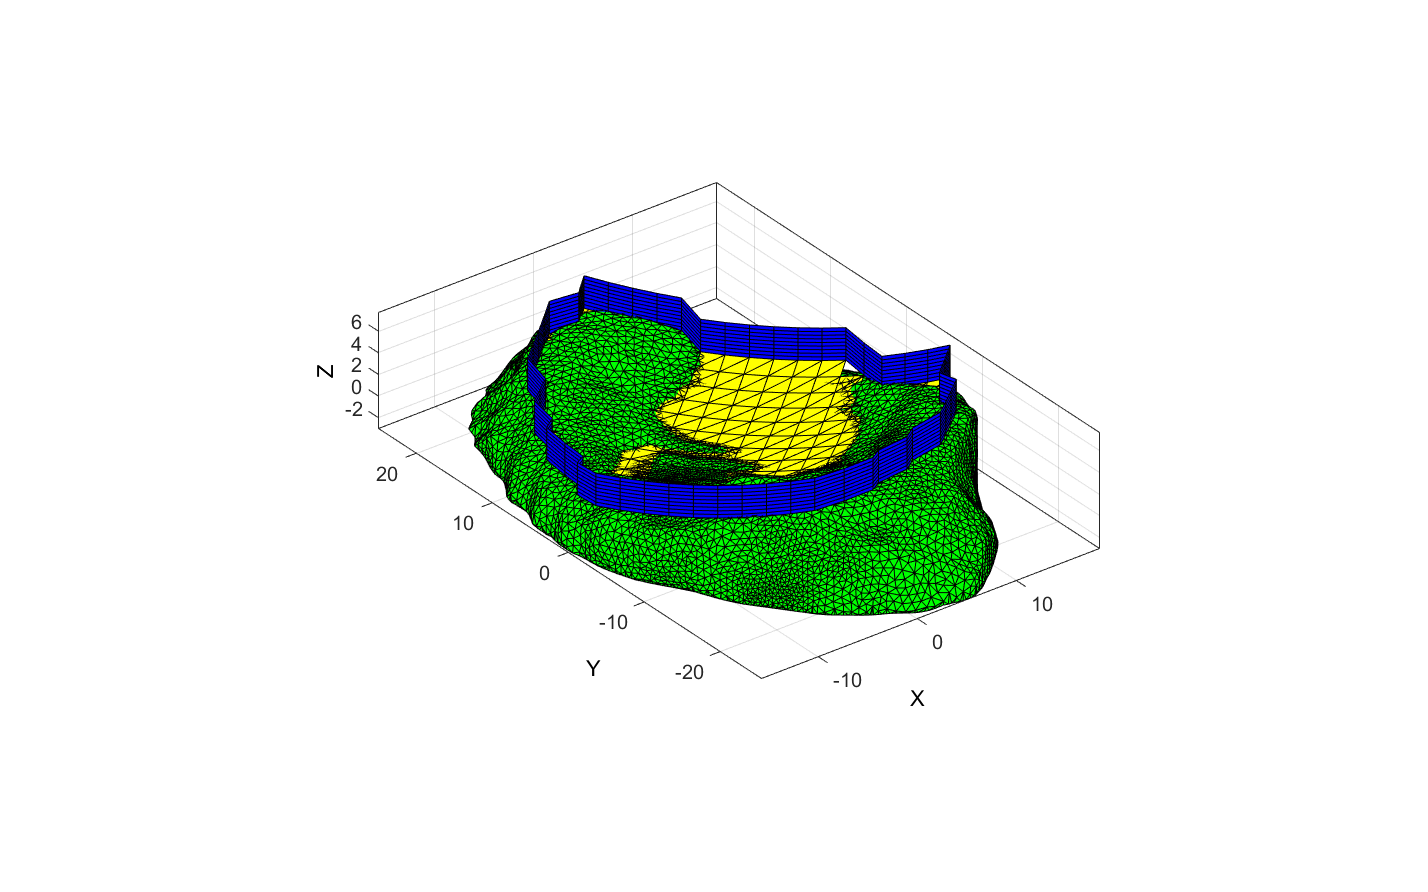

%Visualise the cartilage loft with the glenoid
cFigure; hold on;
%Plot glenoid surface
gpatch(glenoidF,glenoidV,'g','k',1);
axisGeom;
%Plot cartilgae loft
gpatch(cartilageOuterF,cartilageOuterV,'b','k',1);
%Plot the cartilage base
gpatch(cartilageBaseF,cartilageBaseV,'y','k',1);

**NOTE: the above procedure works for a consistent thickness, but is still a bit noisy. This might become cleaner if we use a more refined sphere mesh, or with smoothing later. The noisiness of it does result in areas of the glenoid surface getting missed, so it may be better to have a smoother option at the front end.**

## Extend Along the Smoothed Glenoid Boundary

Now that we have a potentially appropriate boundary, we can extend out from the glenoid face to create a cartilage structure. This could be done using the new patchExtend method, or by using the earlier loft feature of the GIBBON toolbox.

Based on the fact that the patchExtend function needs an edge boundary, which doesn't fit the glenoid face surface, the standard loft function is probably the most useful.

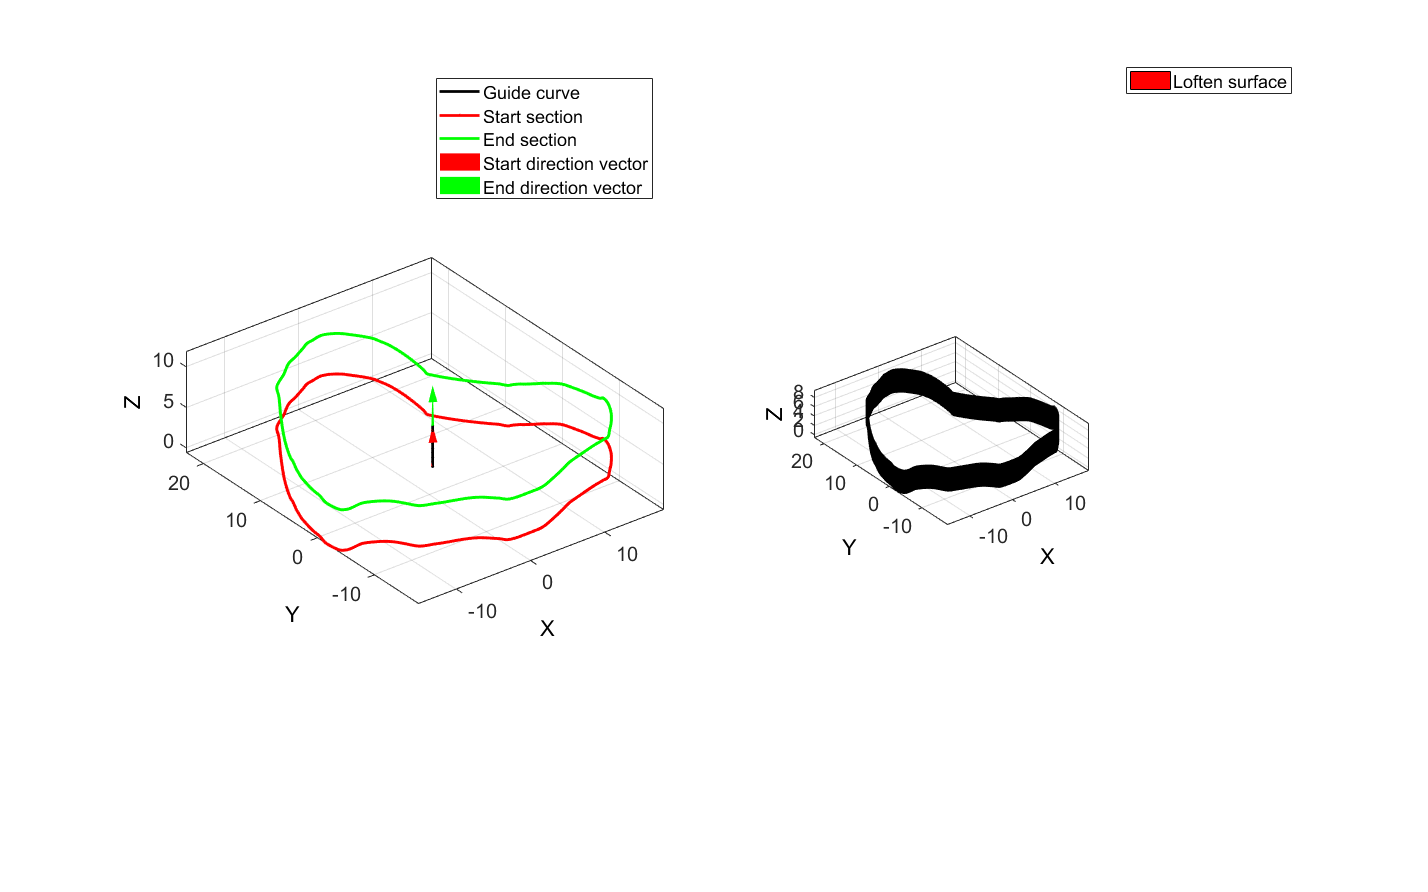

%Create the starting sketch for the cartilage loft
%Smooth out the points on the edge of the glenoid surface
startGlenoidLoft(:,1) = smoothedGlenoidBoundary(:,1);
startGlenoidLoft(:,2) = smoothedGlenoidBoundary(:,2);
startGlenoidLoft(:,3) = smoothedGlenoidBoundary(:,3);

%Delete the last point of these vertices to make the shape discontinous.
%This seems necessary for the evenly sampling curve procedure
startGlenoidLoft = startGlenoidLoft(1:end-1,:);

% % % %Get the XY boundary points
% % % %This is needed later to avoid errors with the evenly sampled curve
% % % k = boundary(startGlenoidLoft(:,1),startGlenoidLoft(:,2));
% % % Vbnd(:,1) = startGlenoidLoft(k,1);
% % % Vbnd(:,2) = startGlenoidLoft(k,2);
% % % Vbnd(:,3) = startGlenoidLoft(k,3);
% % % Vbnd = Vbnd(1:end-1,:); %remove the last point for discontinuity

% % % %Smooth the boundary to a large number of points for clean-ish edges
% % % %Set back to the start glenoid loft variable
% % % startGlenoidLoft = evenlySampleCurve(Vbnd,1000,'pchip',1);
% % % clear k Vbnd

%Create the second sketch by adding the z-translation value
%For now we'll use a 'cartilage' thickness of 5mm, however this should be
%made specific by doing some digging around the gap between the humerus and
%scapula.
maxCartilageThickness = 5;
endGlenoidLoft = [startGlenoidLoft(:,1),startGlenoidLoft(:,2),startGlenoidLoft(:,3)+maxCartilageThickness];
% % % endGlenoidLoft = [Vbnd(:,1),Vbnd(:,2),Vbnd(:,3)+maxCartilageThickness];

%Create a guide curve (some default parameters)
%Should just be a straight line really...
numStepsCurve = 10; %Number of steps for the curve
p1 = mean(startGlenoidLoft,1); %First point
n1 = [0,0,1]; %First direction vector; z direction
p2 = mean(endGlenoidLoft,1); %End point
n2 = [0,0,1]; %End direction vector; z direction
csapsSmoothPar = 1; %Cubic smoothening spline smoothening parameter
f = 0.05; %Extent of tangential nature to boundary curves, surface will remain approximately orthogonal to input curves for f*distance between curves
[Vg] = sweepCurveSmooth(p1,p2,n1,n2,numStepsCurve,csapsSmoothPar,f);

%Create the loft feature
[cartilageOuterF,cartilageOuterV] = sweepLoft(startGlenoidLoft,endGlenoidLoft,n1,n2,Vg);
% % % [cartilageOuterF,cartilageOuterV] = sweepLoft(Vbnd,endGlenoidLoft,n1,n2,Vg);

%Visualise the loft feature
cFigure;
subplot(1,2,1);
hold on;
h(1)=plotV(Vg,'k.-','LineWidth',2);
h(2)=plotV(startGlenoidLoft,'r.-','LineWidth',2);
h(3)=plotV(endGlenoidLoft,'g.-','LineWidth',2);
h(4)=quiverVec(p1,n1,5,'r');
h(5)=quiverVec(p2,n2,5,'g');
legend(h,{'Guide curve','Start section','End section','Start direction vector','End direction vector'});
axisGeom;

subplot(1,2,2); hold on;
h = gpatch(cartilageOuterF,cartilageOuterV,'r','k',1);
axisGeom;
legend(h,{'Loften surface'});
camlight headlight

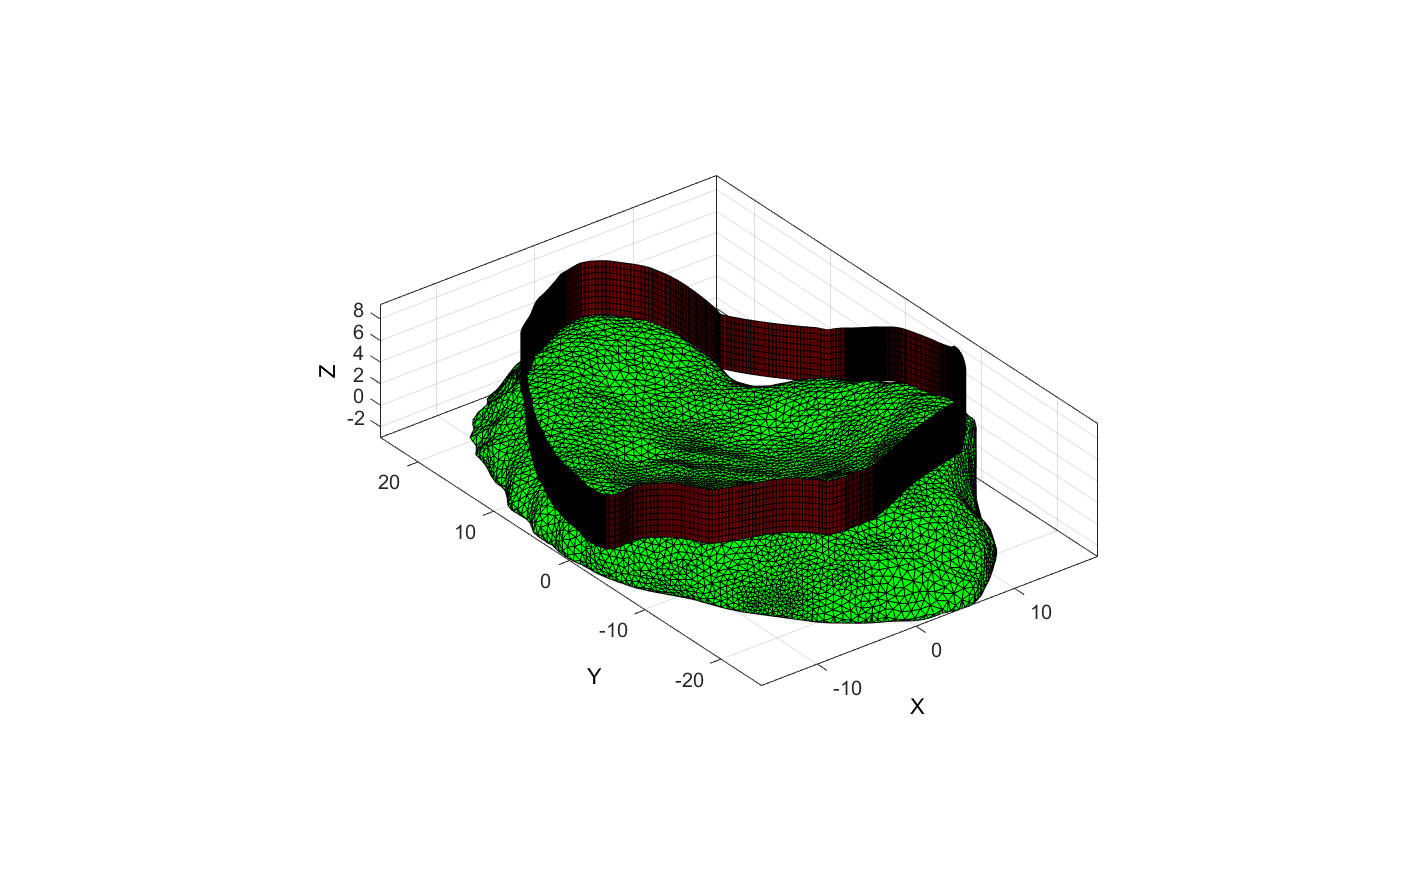

%Visualise the cartilage loft with the glenoid
cFigure; hold on;
%Plot glenoid surface
gpatch(glenoidF,glenoidV,'g','k',1);
axisGeom;
%Plot cartilgae loft
gpatch(cartilageOuterF,cartilageOuterV,'r','k',1);

The above loft procedure provides an outline of the cartilage surface. We can close over the top of it usig the region meshing procedure.

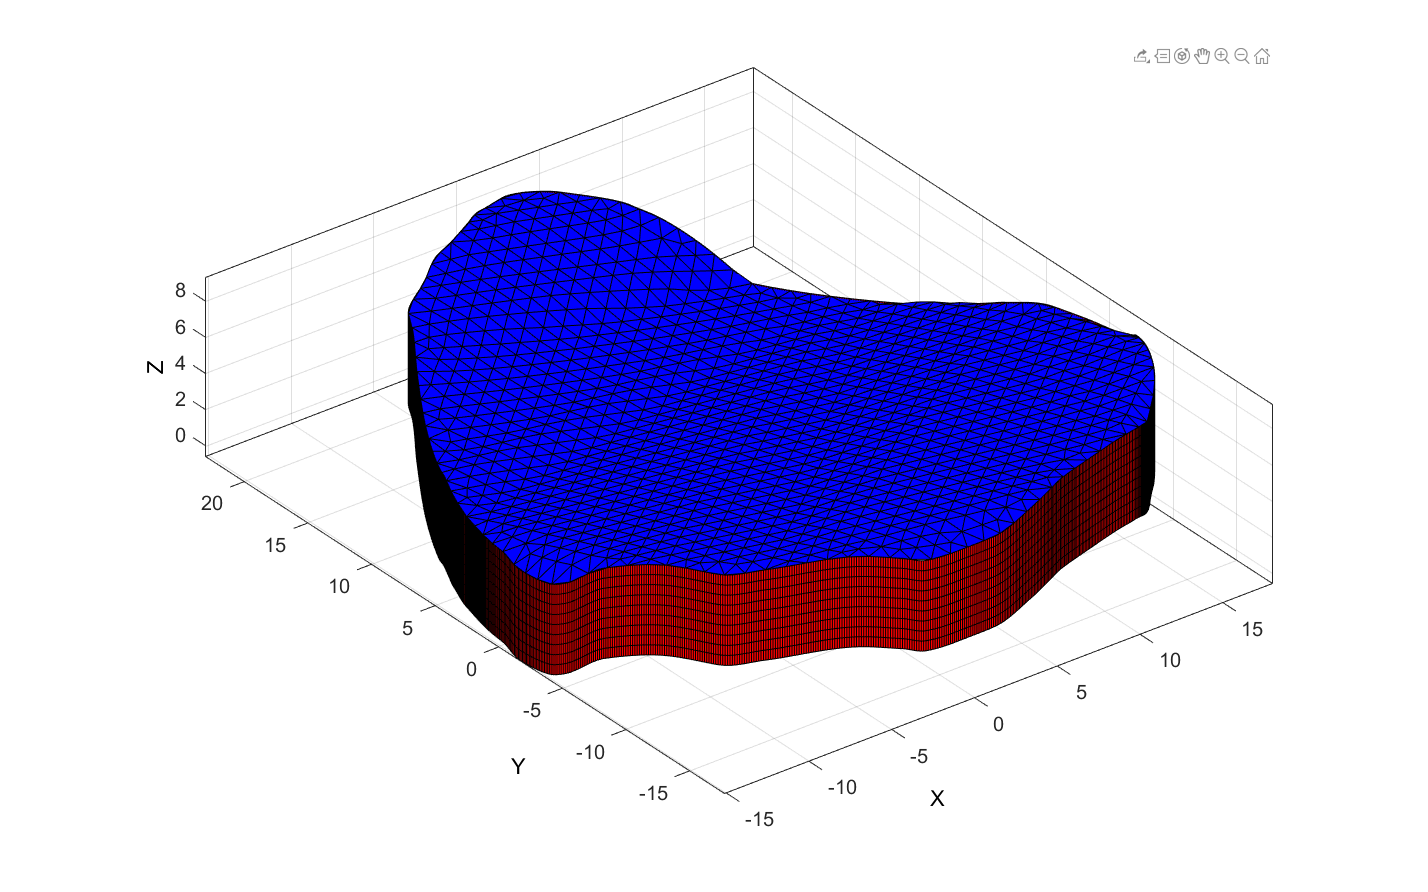

%Get the XY boundary points
%This is needed later to avoid errors with the evenly sampled curve
k = boundary(endGlenoidLoft(:,1),endGlenoidLoft(:,2));
Vbnd(:,1) = endGlenoidLoft(k,1);
Vbnd(:,2) = endGlenoidLoft(k,2);
Vbnd(:,3) = endGlenoidLoft(k,3);
Vbnd = Vbnd(1:end-1,:); %remove the last point for discontinuity

%Smooth the boundary to a large number of points for clean-ish edges
Vsmooth = evenlySampleCurve(Vbnd,1000,'pchip',1);

%Place in the region cell for the meshing procedure
regionCell = {Vsmooth};

% % % %Use the end loft region as the outer points of the mesh to fill

% % % %Place in the region cell for the meshing procedure
% % % regionCell = {endGlenoidLoft};

%Defining a region and control parameters (See also |regionTriMesh2D|)
pointSpacing = 0.5; %Desired point spacing (half of bone meshes for now)
resampleCurveOpt = 1; %option for resampling the curve
interpMethod = 'linear'; %or 'natural'
[cartilageTopF,cartilageTopV] = regionTriMesh3D(regionCell,pointSpacing,resampleCurveOpt,interpMethod);

%Visualise the two surfaces together
cFigure; hold on;
gpatch(cartilageOuterF,cartilageOuterV,'r','k',1);
gpatch(cartilageTopF,cartilageTopV,'b','k',1);
axisGeom;



%Grab the XY coordinates of the smoothed glenoid boundary


%Place in the region cell for the meshing procedure
regionCell = {Vsmooth};

%Defining a region and control parameters (See also |regionTriMesh2D|)
pointSpacing = 1; %Desired point spacing (same as bone meshes for now)
resampleCurveOpt = 1; %option for resampling the curve
interpMethod = 'linear'; %or 'natural'
[cartilageTopF,cartilageTopV] = regionTriMesh3D(regionCell,pointSpacing,resampleCurveOpt,interpMethod);

%Create copies for warping
cartilageTopWarpedF = cartilageTopF;
cartilageTopWarpedV = cartilageTopV;

%Plot meshed model
cFigure;
title('Top Cartilage Mesh Flat','FontSize',15);
xlabel('X','FontSize',15);ylabel('Y','FontSize',15); zlabel('Z','FontSize',15);
hold on;
gpatch(cartilageTopF,cartilageTopV,'b');
gpatch(glenoidF,glenoidV,'g');
plotV(Vsmooth,'r-','LineWidth',2);
axis equal; view(3); axis tight;  grid on;  set(gca,'FontSize',15);
camlight headlight;

%Set the min cartilage thickness. Start with a value of 5mm
minCartilageThickness = 1.14;

%Create the 3 coordinate points for the X polynomial
x_Xpts = [min(cartilageTopV(:,1)), 0, max(cartilageTopV(:,1))];
y_Xpts = [0, minCartilageThickness, 0];

%Fit the x-polynomial and get the equation
x_P = polyfit(x_Xpts,y_Xpts,2);

%Create the 3 coordinate points for the Y polynomial
x_Ypts = [min(cartilageTopV(:,2)), mean(cartilageTopV(:,2)), max(cartilageTopV(:,2))];
y_Ypts = [0, minCartilageThickness, 0]; %set to curvature radius

%Fit the x-polynomial and get the equation
y_P = polyfit(x_Ypts,y_Ypts,2);

%Warp the disc Z-axis based on the two quadratic functions
cartilageTopWarpedV(:,3) = cartilageTopV(:,3) - (polyval(x_P,cartilageTopV(:,1))) - (polyval(y_P,cartilageTopV(:,2)));

%Plot the warped mesh model and include the glenoid
cFigure; hold on
title('Top Cartilage Mesh Warped','FontSize',15);
xlabel('X','FontSize',15);ylabel('Y','FontSize',15); zlabel('Z','FontSize',15);
gpatch(glenoidF,glenoidV,'g','k',1);
gpatch(cartilageTopWarpedF,cartilageTopWarpedV,'y');
gpatch(cartilageTopF,cartilageTopV,'b');
axis equal; view(3); axis tight;  grid on;  set(gca,'FontSize',15);
camlight headlight;




## Create a Loft Feature to Extend to for the Cartilage

The next step is to create a flat 3D mesh that will represent the end point for the glenoid cartilage. We can do this using the points on the glenoid border combined with our knowledge of cartilage thickness at the mid point combined with the radius curvature of the glenoid cartilage. In this example, both come from the Walia et al. studies, however cartilage thickness at the glenoid centre could be estimated based on our knowledge of the position of the humerus relative to the glenoid. Radius curvature probably needs to be taken from the literature, unless we want to match the glenoid surface (probably too difficult).

%Grab the XY coordinates of the smoothed glenoid boundary
X = smoothedGlenoidBoundary(:,1);
Y = smoothedGlenoidBoundary(:,2);

%Create a Z-point for these at minimum cartilage thickness, which will end
%up being above the origin point, so is fairly straight forward to specify
minCartilageThickness = 1.14;
Z = ones(length(X),1)*minCartilageThickness;

%Convert this to a vertices structur
V = [X(:) Y(:) Z(:)];

%Delete the last point of these vertices to make the shape discontinous.
%This seems necessary for the region meshing process
V = V(1:end-1,:);

%Get the XY boundary points
%This is needed later to avoid errors with the evenly sampled curve
k = boundary(V(:,1),V(:,2));
Vbnd(:,1) = V(k,1);
Vbnd(:,2) = V(k,2);
Vbnd(:,3) = V(k,3);
Vbnd = Vbnd(1:end-1,:); %remove the last point for discontinuity

%Smooth the boundary to a large number of points for clean-ish edges
Vsmooth = evenlySampleCurve(Vbnd,1000,'pchip',1);

%Place in the region cell for the meshing procedure
regionCell = {Vsmooth};

%Defining a region and control parameters (See also |regionTriMesh2D|)
pointSpacing = 1; %Desired point spacing (same as bone meshes for now)
resampleCurveOpt = 1; %option for resampling the curve
interpMethod = 'linear'; %or 'natural'
[cartilageTopF,cartilageTopV] = regionTriMesh3D(regionCell,pointSpacing,resampleCurveOpt,interpMethod);

%Plot meshed model
cFigure;
title('Top Cartilage Mesh Flat','FontSize',15);
xlabel('X','FontSize',15);ylabel('Y','FontSize',15); zlabel('Z','FontSize',15);
hold on;
gpatch(cartilageTopF,cartilageTopV,'b');
gpatch(glenoidF,glenoidV,'b');
plotV(Vsmooth,'b-','LineWidth',2);
axis equal; view(3); axis tight;  grid on;  set(gca,'FontSize',15);
camlight headlight;

The above works, but could still have smoother edges. The issue here is most likely that these edge points are being guided by the glenoid surface and the points manually specified/connected to its surface. A much smoother outline could probably be generated relatively easy.

This top cartilage disc surface is currently sitting at a z-level of minimum thickness that will sit at the glenoid centre. To get the radius curvature that we require, the outer edges need to be lifted up along the z-axis by a specified amount. We want the disc to be perturbed relative to its max/min X and Y points relative to the centre, based on a quadratic polynomial. We know that at the mid point of the ellipse (i.e. [0,0]) that the perturbation to the disc should be zero, so that gives us one coordinate (i.e. [0, 0]). At the max and min of the coordinates we want the disc to be perturbed upwards by the maximum cartilage thickness, which we will specify appropriately later based on humerus position, so that gives us the remaining two points (i.e. [min(X),maxThickness] & [max(X),maxThickness]). With these three coordinates we can fit a quadratic polynomial that will add to the Z value based on the curve fit to it.

%Set the max cartilage thickness. Start with a value of 5mm
maxCartilageThickness = 5;

%Create the 3 coordinate points for the X polynomial
x_Xpts = [min(cartilageTopV(:,1)), 0, max(cartilageTopV(:,1))];
y_Xpts = [maxCartilageThickness, 0, maxCartilageThickness]; %set to curvature radius

%Fit the x-polynomial and get the equation
x_P = polyfit(x_Xpts,y_Xpts,2);

%Create the 3 coordinate points for the Y polynomial
x_Ypts = [min(cartilageTopV(:,2)), mean(cartilageTopV(:,2)), max(cartilageTopV(:,2))];
y_Ypts = [maxCartilageThickness, 0, maxCartilageThickness]; %set to curvature radius

%Fit the x-polynomial and get the equation
y_P = polyfit(x_Ypts,y_Ypts,2);

%Warp the disc Z-axis based on the two quadratic functions
cartilageTopV(:,3) = (polyval(x_P,cartilageTopV(:,1))) + (polyval(y_P,cartilageTopV(:,2)));

%Plot the warped mesh model and include the glenoid
cFigure; hold on
title('Top Cartilage Mesh Warped','FontSize',15);
xlabel('X','FontSize',15);ylabel('Y','FontSize',15); zlabel('Z','FontSize',15);
gpatch(glenoidF,glenoidV,'g','k',1);
gpatch(cartilageTopF,cartilageTopV,'b');
axis equal; view(3); axis tight;  grid on;  set(gca,'FontSize',15);
camlight headlight;

## Extend Along the Smoothed Glenoid Boundary

Now that we have a potentially appropriate boundary, we can extend out from the glenoid face to create a cartilage structure. This could be done using the new patchExtend method, or by using the earlier loft feature of the GIBBON toolbox.

Based on the fact that the patchExtend function needs an edge boundary, which doesn't fit the glenoid face surface, the standard loft function is probably the most useful.

***TODO: fix up variable naming through here...***

%Create the starting sketch from the boundary points
%This could be smoothed more if necessary
V1 = smoothedGlenoidBoundary;

%Create the second sketch by adding the z-translation value
%For now we'll use a 'cartilage' thickness of 5mm, however this should be
%made specific by doing some digging around the gap between the humerus and
%scapula.
V2 = [V1(:,1),V1(:,2),V1(:,3)+5];

%Create a guide curve (some default parameters)
%Should just be a straight line really...
numStepsCurve = 10; %Number of steps for the curve
p1 = mean(V1,1); %First point
n1 = [0,0,1]; %First direction vector; z direction
p2 = mean(V2,1); %End point
n2 = [0,0,1]; %End direction vector; z direction
csapsSmoothPar = 1; %Cubic smoothening spline smoothening parameter
f = 0.05; %Extent of tangential nature to boundary curves, surface will remain approximately orthogonal to input curves for f*distance between curves
[Vg] = sweepCurveSmooth(p1,p2,n1,n2,numStepsCurve,csapsSmoothPar,f);

%Create the loft feature
[cartilageF,cartilageV] = sweepLoft(V1,V2,n1,n2,Vg);

%Visualise the loft feature
cFigure;
subplot(1,2,1);
hold on;
h(1)=plotV(Vg,'k.-','LineWidth',2);
h(2)=plotV(V1,'r.-','LineWidth',2);
h(3)=plotV(V2,'g.-','LineWidth',2);
h(4)=quiverVec(p1,n1,5,'r');
h(5)=quiverVec(p2,n2,5,'g');
legend(h,{'Guide curve','Start section','End section','Start direction vector','End direction vector'});
axisGeom;

subplot(1,2,2); hold on;
h = gpatch(cartilageF,cartilageV,'r','k',1);
axisGeom;
legend(h,{'Loften surface'});
camlight headlight
%Visualise the cartilage loft with the glenoid
cFigure; hold on;
%Plot glenoid surface
gpatch(glenoidF,glenoidV,'g','k',1);
axisGeom;
%Plot cartilgae loft
gpatch(cartilageF,cartilageV,'r','k',1);
%2D
%Defining a region
regionCell={unique(V2(1:end-1,1:2),'rows')}; %A region between V1 and V2 (V2 forms a hole inside V1)
plotOn = 1; %This turns on/off plotting
pointSpacing = 0.5; %Desired point spacing
resampleCurveOpt = 0; %Option to turn on/off resampling of input boundary curves

[F,V] = regionTriMesh2D(regionCell,pointSpacing,resampleCurveOpt,plotOn);
plotV(V2,'b-','LineWidth',2);
axis tight;
drawnow;


**WHY DOES IT CREATE A BOUNDARY ACROSS THE MIDDLE?????**



%3D

%Self triangulate the top edge
%The points V2 equate to the top edge that can be used for remeshing
%Remove non unique points as this causes errors in interpolation
regionCell = {unique(V2,'rows')};

%Defining a region and control parameters (See also |regionTriMesh2D|)
pointSpacing = 0.1; %Desired point spacing
resampleCurveOpt = 1;
interpMethod = 'linear'; %or 'natural'
[cartilageTopF,cartilageTopV] = regionTriMesh3D(regionCell,pointSpacing,resampleCurveOpt,interpMethod);

%Visualise closed mesh
cFigure; hold on;
%Plot cartilgae loft
gpatch(cartilageF,cartilageV,'r','k',1);
%Plot closed top
gpatch(cartilageTopF,cartilageTopV,'g','k',1);
axisGeom;

***NOTE: The below code relates to using the patchExtend function and the need to generate an edge border. The below might be useful to have later, with one of the additional things to figure out how to include points on the ployshape line as 'in.'***

Before doing this we need to remove the faces/vertices that sit inside the smoothed boundary region so that the top of the glenoid surface becomes an open edge.

%Create a polyshape based on the smoothed points
polyin = polyshape(smoothedGlenoidBoundary(:,1),smoothedGlenoidBoundary(:,2));

%Plot poly and all points
plot(polyin)
hold on
scatter(glenoidV(:,1),glenoidV(:,2),2,'k','filled')

%Determine which glenoid vertices are within the smoothed boundary
inFace = isinterior(polyin,glenoidV(:,1),glenoidV(:,2));

%Plot those that are in and out with green and red
scatter(glenoidV(inFace,1),glenoidV(inFace,2),2,'g','filled')
scatter(glenoidV(~inFace,1),glenoidV(~inFace,2),2,'r','filled')

%Create a detached mesh set based on whether to keep the vertices or not
logicKeep = all(~inFace(glenoidF),2);
[glenoidEdgeF,glenoidEdgeV] = patchCleanUnused(glenoidF(logicKeep,:),glenoidV);

%Visualise new mesh
cFigure; hold on
gpatch(glenoidF,glenoidV,'w','none',0.3);
gpatch(glenoidEdgeF,glenoidEdgeV,'r','k',1);
axisGeom;

With this newly edged glenoid we can now examine how a basic method would work extending the edges by 20mm.

%Get the surface and boundary edges 
Eb = patchBoundary(glenoidEdgeF,glenoidEdgeV); %All boundary edges (including bottom)
VE = patchCentre(Eb,glenoidEdgeV); %Edge centre coordinates

%Find the closest point in the edge boundary coordinates to the earlier
%smoothed boundary points on the glenoid face


### UP TO HERE!


logicTop = VE(:,3)>0; %Logic for top edges (Z-coordinate above 0)
Eb = Eb(logicTop,:); %Set of edges at the top

%Set the options
optionStruct.numSteps = [];
optionStruct.plotOn = 1;
optionStruct.meshType = [];
optionStruct.globalDirection = [0,0,1]; %z-direction to extend in
optionStruct.extendDistance = 20; %Extend distance
optionStruct.extendMethod = 1; %Method to use for extruding; equal offset along local direction

%Extend
[cartilageF,cartilageV] = patchExtend(glenoidF,glenoidV,smoothedGlenoidBoundary,optionStruct);


%Set the option struct for patchExtend
optionStruct.numSteps = [];
optionStruct.plotOn = 0;
optionStruct.meshType = [];
optionStruct.globalDirection = [0,0,1]; %z-direction to extend in
optionStruct.extendDistance = 20; %Extend distance


We can then have a look at how the different methods work extending the surface by a standard distance of 20mm.

Do the processes involved with the above manually to get the patches and only plot the normals that we want.

% % % %Get the patch normals
% % % [N,Vn] = patchNormal(scapulaF_slice,scapulaV_slice);   

The likely solution is to identify the normals that have a predominantly positive z-direction component, and subsequently lacking a real X and Y direction component.

% % % %Test plot faces of normals that have a small X and Y normal component
% % % plotNormals = logical(abs(N(:,1)) < 0.1 & logical(abs(N(:,2) < 0.1)))
% % % 
% % % %Visualise
% % % cFigure; hold on;
% % % hp1 = gpatch(scapulaF_slice(plotNormals),scapulaV_slice(scapulaF_slice(plotNormals),'gw','k',1);
% % % hp2 = gpatch(scapulaF_slice(~plotNormals,:),scapulaV_slice(~plotNormals,:),'rw','k',1);
% % % legend([hp1 hp2],{'Selected Normals','Unselected Normals'})
% % % axisGeom; axis manual; camlight headligth;
% % % colormap gjet;
% % % set(gca,'FontSize',fontSize);

***TODO: plotting of selected faces not working - check how this is done in other help functions like the patchNormFix HELP.***

TODO: extract the normals we want.

NOTE: N refers to the normal direction, while Vn refers to the 3d location (I think...). Check the patchNormPlot code for how it can be used. To achieve the goal, effectively we want to identify the normals that are located within a specific boundary (i.e. close to the glenoid) and those that point in a certain direction above a threshold (i.e. upwards/upwards above a specific angle threshold from the glenoid).